# 2P cell gain analysis

## single cell analysis


% no neuropil correction - first pass
% by cell soma, identified as responsive
addpath('456_1 flfl','458_2 flfl','458_3 flfl','458_5 flfl','468_1 flfl','456_2 tecta flfl','458_1 tecta flfl','460_2 tecta flfl','460_3 tecta flfl','460_5 tecta flfl','460_6 tecta flfl','472_2 flfl','472_1 flfl','480_2 tecta flfl','480_3 flfl','486_1 flfl','488_1 tecta flfl','487_2 tecta flfl','487_1 flfl')

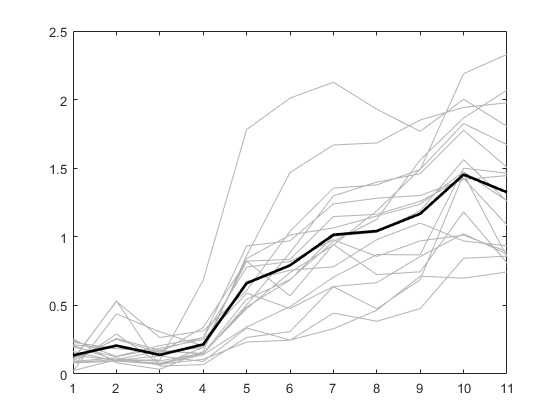


% 6 kHz soma gain - control
con1 = load('C1-exp456 m1 6khz 10-60 db 5 db steps 6 reps_ICdata.mat'); %456_1
con1.numLevels = size(con1.ROIdF,1);
con1.numROI = size(con1.ROIdF,2);

con2 = load('C1-exp458 m2 flfl 6 khz 4 rep 10-70 db atten 5 db steps R IC_ICdata.mat'); %458_2
con2.numLevels = size(con2.ROIdF,1);
con2.numROI = size(con2.ROIdF,2);

con3 = load('C1-exp458 m3 flfl 6 khz 6 rep 10-60 db atten 5 db steps L IC_ICdata.mat'); %458_3
con3.numLevels = size(con3.ROIdF,1);
con3.numROI = size(con3.ROIdF,2);

con4 = load('C1-exp458 m5 tmem16flfl 6 khz 4 rep 5 db steps 10-70 RIC_ICdata.mat'); %458_5
con4.numLevels = size(con4.ROIdF,1);
con4.numROI = size(con4.ROIdF,2);

con5 = load('C1-20211015 exp467 mouse 1 tmem16flfl 6 khz gain 6 rep 10-60 db atten_ICdata.mat'); %468_1
con5.numLevels = size(con5.ROIdF,1);
con5.numROI = size(con5.ROIdF,2);

con6 = load('C1-20211119 exp480 mouse 3tmem16aflfl 6 khz gain R ic 10-60 db 5 db steps_ICdata.mat'); %468_1
con6.numLevels = size(con6.ROIdF,1);
con6.numROI = size(con6.ROIdF,2);

minLevel = 0.1;
% mean by animal - all cells and mean
figure;
for x = 1:con1.numROI
    plot([con1.numLevels:-1:1],[con1.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con1.numLevels
    con1.mean(y) = mean([con1.ROIdF(y,:).max]);
    con1.meanfull(y) = mean([con1.ROIdF(y,:).max]);
     if con1.mean(y) < minLevel
        con1.mean(y) = NaN
    end
end
plot([con1.numLevels:-1:1],con1.mean,'k','LineWidth',2)

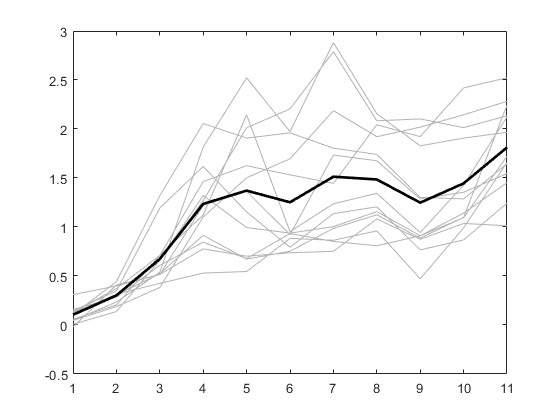


figure;
for x = 1:con2.numROI
    plot([con2.numLevels:-1:1],[con2.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con2.numLevels
    con2.mean(y) = mean([con2.ROIdF(y,:).max]);
    con2.meanfull(y) = mean([con2.ROIdF(y,:).max]);
         if con2.mean(y) < minLevel
        con2.mean(y) = NaN
    end
end
plot([con2.numLevels:-1:1],con2.mean,'k','LineWidth',2)


figure;
for x = 1:con3.numROI
    plot([con3.numLevels:-1:1],[con3.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con3.numLevels
    con3.mean(y) = mean([con3.ROIdF(y,:).max]);
    con3.meanfull(y) = mean([con3.ROIdF(y,:).max]);
    if con3.mean(y) < minLevel
        con3.mean(y) = NaN
    end
end

con3 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×6 struct]
        ROIdF: [11×6 struct]
       WholeF: [1×11 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 6
         mean: [1.0042 0.9438 0.8405 0.9484 1.0492 0.9777 0.6860 0.3049 NaN]
     meanfull: [1.0042 0.9438 0.8405 0.9484 1.0492 0.9777 0.6860 0.3049 0.0478]


con3 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×6 struct]
        ROIdF: [11×6 struct]
       WholeF: [1×11 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 6
         mean: [1.0042 0.9438 0.8405 0.9484 1.0492 0.9777 0.6860 0.3049 NaN 0.1524 NaN]
     meanfull: [1.0042 0.9438 0.8405 0.9484 1.0492 0.9777 0.6860 0.3049 0.0478 0.1524 0.0021]


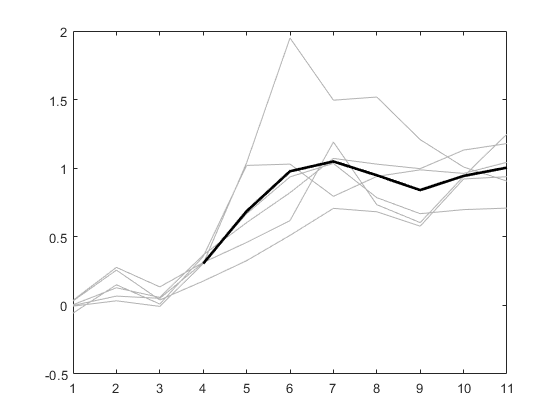

plot([con3.numLevels:-1:1],con3.mean,'k','LineWidth',2)

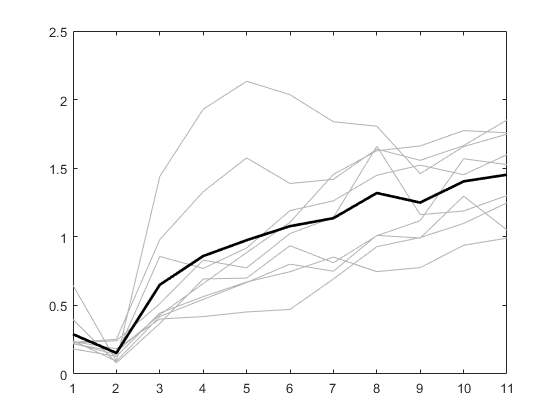


figure;
for x = 1:con4.numROI
    plot([con4.numLevels:-1:1],[con4.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con4.numLevels
    con4.mean(y) = mean([con4.ROIdF(y,:).max]);
    con4.meanfull(y) = mean([con4.ROIdF(y,:).max]);
    if con4.mean(y) < minLevel
        con4.mean(y) = NaN
    end
end
plot([con4.numLevels:-1:1],con4.mean,'k','LineWidth',2)


figure;
for x = 1:con5.numROI
    plot([con5.numLevels:-1:1],[con5.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con5.numLevels
    con5.mean(y) = mean([con5.ROIdF(y,:).max]);
    con5.meanfull(y) = mean([con5.ROIdF(y,:).max]);
    if con5.mean(y) < minLevel
        con5.mean(y) = NaN
    end
end

con5 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×5 struct]
        ROIdF: [11×5 struct]
       WholeF: [1×11 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 5
         mean: [1.4946 1.4777 1.4027 1.6910 1.4806 1.4829 1.4755 1.1839 1.1078 0.6672 NaN]
     meanfull: [1.4946 1.4777 1.4027 1.6910 1.4806 1.4829 1.4755 1.1839 1.1078 0.6672 0.0610]


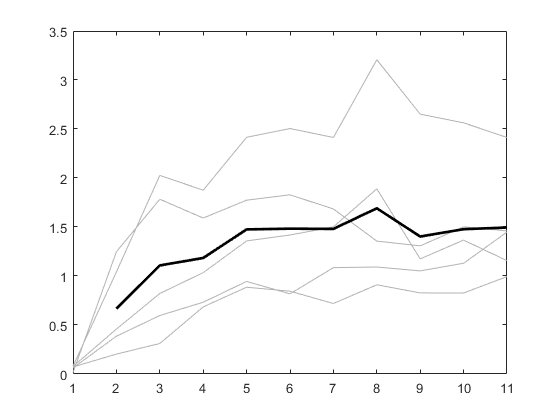

plot([con5.numLevels:-1:1],con5.mean,'k','LineWidth',2)


figure;
for x = 1:con6.numROI
    plot([con6.numLevels:-1:1],[con6.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con6.numLevels
    con6.mean(y) = mean([con6.ROIdF(y,:).max]);
    con6.meanfull(y) = mean([con6.ROIdF(y,:).max]);
    if con6.mean(y) < minLevel
        con6.mean(y) = NaN
    end
end

con6 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×8 struct]
        ROIdF: [11×8 struct]
       WholeF: [1×11 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 8
         mean: [1.0316 1.2186 1.2337 1.2203 1.2387 1.0242 0.9689 0.7654 0.6105 0.2758 NaN]
     meanfull: [1.0316 1.2186 1.2337 1.2203 1.2387 1.0242 0.9689 0.7654 0.6105 0.2758 0.0723]


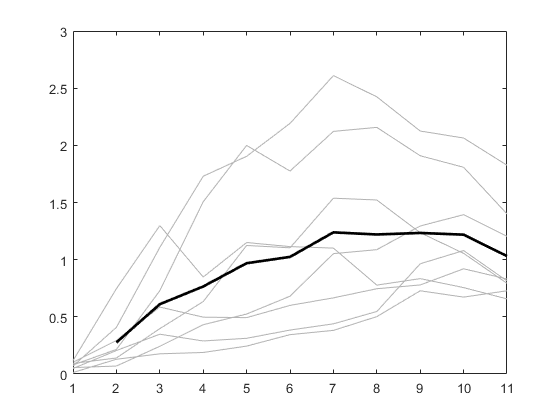

plot([con6.numLevels:-1:1],con6.mean,'k','LineWidth',2)

Concells = [con1.numROI,con2.numROI,con3.numROI,con4.numROI,con5.numROI,con6.numROI];

% 6 kHz - cKO
cko1 = load('C1-exp456 m2 6khz 10-60 db 5 db steps 6 reps 2x_ICdata.mat'); %456_2
cko1.numLevels = size(cko1.ROIdF,1);
cko1.numROI = size(cko1.ROIdF,2);

cko2 = load('C1-exp458 m1 tecta flfl 6 khz 4 rep 10-60 db atten 5 db steps_ICdata.mat'); %456_2
cko2.numLevels = size(cko2.ROIdF,1);
cko2.numROI = size(cko2.ROIdF,2);

cko6 = load('C1-exp460 mouse2 tecta flfl 6 khz 4 rep 10-60 db atten 5 db steps_ICdata'); %460_2
cko6.numLevels = size(cko6.ROIdF,1);
cko6.numROI = size(cko6.ROIdF,2);

cko3 = load('C1-exp460 mouse6 R IC tecta flfl 6 khz 4 rep 10-60 db atten 5 db steps_ICdata.mat'); %460_6
cko3.numLevels = size(cko3.ROIdF,1);
cko3.numROI = size(cko3.ROIdF,2);

cko4 = load('C1-exp460 mouse5 L IC tecta flfl 6 khz 4 rep 10-60 db atten 5 db steps_ICdata.mat'); %460_5
cko4.numLevels = size(cko4.ROIdF,1);
cko4.numROI = size(cko4.ROIdF,2);

cko5 = load('C1-exp460 mouse3 R IC tecta flfl 6 khz 4 rep 10-70 db atten 5 db steps_ICdata.mat'); %460_3
cko5.numLevels = size(cko5.ROIdF,1);
cko5.numROI = size(cko5.ROIdF,2);

cko7 = load('C1-20211119 exp480 mouse 2 tecta tmem16aflfl 6 khz gain L ic 10-60 db 5 db steps_ICdata.mat'); 
cko7.numLevels = size(cko7.ROIdF,1);
cko7.numROI = size(cko7.ROIdF,2);

cko8 = load('C1-20211229 exp488 mouse 1 tmem16aflfl 6 khz gain 10-70db atten 4reps_ICdata.mat'); 
cko8.numLevels = size(cko8.ROIdF,1);
cko8.numROI = size(cko8.ROIdF,2);

minLevel = 0.1;
figure;
for x = 1:cko1.numROI
    plot([cko1.numLevels:-1:1],[cko1.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko1.numLevels
    cko1.mean(y) = mean([cko1.ROIdF(y,:).max]);
    cko1.meanfull(y) = mean([cko1.ROIdF(y,:).max]);
    if cko1.mean(y) < minLevel
        cko1.mean(y) = NaN
    end
end

cko1 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×3 struct]
        ROIdF: [11×3 struct]
       WholeF: [1×11 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 3
         mean: [1.9771 2.0388 1.8586 1.9104 1.5318 1.2257 0.4293 0.2051 0.1080 0.2819 NaN]
     meanfull: [1.9771 2.0388 1.8586 1.9104 1.5318 1.2257 0.4293 0.2051 0.1080 0.2819 0.0752]


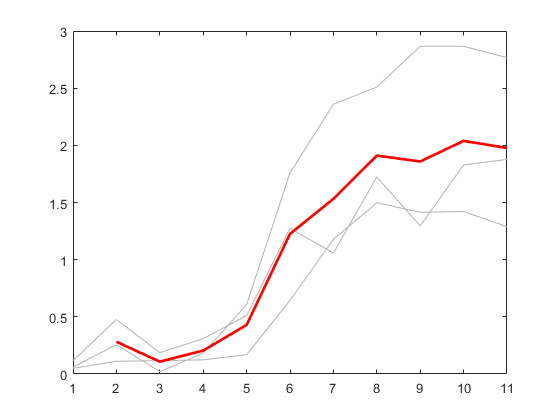

plot([cko1.numLevels:-1:1],cko1.mean,'r','LineWidth',2)


figure;
for x = 1:cko2.numROI
    plot([cko2.numLevels:-1:1],[cko2.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko2.numLevels
    cko2.mean(y) = mean([cko2.ROIdF(y,:).max]);
    cko2.meanfull(y) = mean([cko2.ROIdF(y,:).max]);
     if cko2.mean(y) < minLevel
        cko2.mean(y) = NaN
    end
end

cko2 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×13 struct]
        ROIdF: [11×13 struct]
       WholeF: [1×11 struct]
       allROI: {1×13 cell}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 13
         mean: [4.2002 3.1437 1.5353 0.1883 0.1087 0.3953 NaN]
     meanfull: [4.2002 3.1437 1.5353 0.1883 0.1087 0.3953 0.0481]


cko2 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×13 struct]
        ROIdF: [11×13 struct]
       WholeF: [1×11 struct]
       allROI: {1×13 cell}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 13
         mean: [4.2002 3.1437 1.5353 0.1883 0.1087 0.3953 NaN 0.1792 0.2047 NaN]
     meanfull: [4.2002 3.1437 1.5353 0.1883 0.1087 0.3953 0.0481 0.1792 0.2047 0.0564]


cko2 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×13 struct]
        ROIdF: [11×13 struct]
       WholeF: [1×11 struct]
       allROI: {1×13 cell}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 13
         mean: [4.2002 3.1437 1.5353 0.1883 0.1087 0.3953 NaN 0.1792 0.2047 NaN NaN]
     meanfull: [4.2002 3.1437 1.5353 0.1883 0.1087 0.3953 0.0481 0.1792 0.2047 0.0564 0.0608]


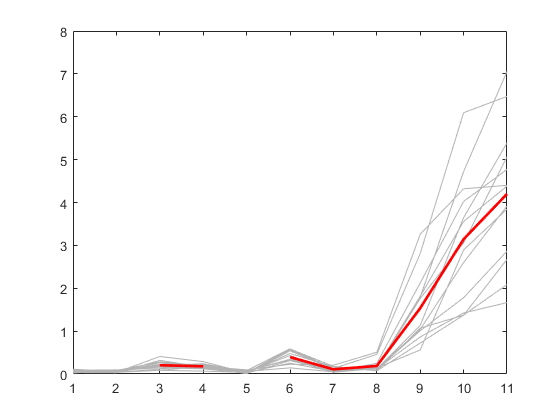

plot([cko2.numLevels:-1:1],cko2.mean,'r','LineWidth',2)


figure;
for x = 1:cko3.numROI
    plot([cko3.numLevels:-1:1],[cko3.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko3.numLevels
    cko3.mean(y) = mean([cko3.ROIdF(y,:).max]);
    cko3.meanfull(y) = mean([cko3.ROIdF(y,:).max]);
     if cko3.mean(y) < minLevel
        cko3.mean(y) = NaN
    end
end

cko3 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×15 struct]
        ROIdF: [11×15 struct]
       WholeF: [1×11 struct]
       allROI: {1×15 cell}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 15
         mean: [2.5964 2.6042 2.5422 2.4392 2.1987 1.8662 0.6230 NaN]
     meanfull: [2.5964 2.6042 2.5422 2.4392 2.1987 1.8662 0.6230 0.0726]


cko3 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×15 struct]
        ROIdF: [11×15 struct]
       WholeF: [1×11 struct]
       allROI: {1×15 cell}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 15
         mean: [2.5964 2.6042 2.5422 2.4392 2.1987 1.8662 0.6230 NaN NaN]
     meanfull: [2.5964 2.6042 2.5422 2.4392 2.1987 1.8662 0.6230 0.0726 0.0485]


cko3 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×15 struct]
        ROIdF: [11×15 struct]
       WholeF: [1×11 struct]
       allROI: {1×15 cell}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 15
         mean: [2.5964 2.6042 2.5422 2.4392 2.1987 1.8662 0.6230 NaN NaN NaN]
     meanfull: [2.5964 2.6042 2.5422 2.4392 2.1987 1.8662 0.6230 0.0726 0.0485 0.0698]


cko3 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×15 struct]
        ROIdF: [11×15 struct]
       WholeF: [1×11 struct]
       allROI: {1×15 cell}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 15
         mean: [2.5964 2.6042 2.5422 2.4392 2.1987 1.8662 0.6230 NaN NaN NaN NaN]
     meanfull: [2.5964 2.6042 2.5422 2.4392 2.1987 1.8662 0.6230 0.0726 0.0485 0.0698 0.0380]


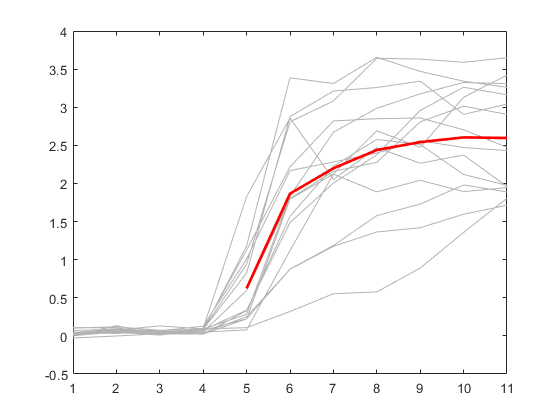

plot([cko3.numLevels:-1:1],cko3.mean,'r','LineWidth',2)


figure;
for x = 1:cko4.numROI
    plot([cko4.numLevels:-1:1],[cko4.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko4.numLevels
    cko4.mean(y) = mean([cko4.ROIdF(y,:).max]);
    cko4.meanfull(y) = mean([cko4.ROIdF(y,:).max]);
     if cko4.mean(y) < minLevel
        cko4.mean(y) = NaN
    end
end

cko4 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×8 struct]
        ROIdF: [11×8 struct]
       WholeF: [1×11 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 8
         mean: [1.9579 1.8694 1.6073 1.4900 1.2842 1.2580 0.8437 0.5098 NaN]
     meanfull: [1.9579 1.8694 1.6073 1.4900 1.2842 1.2580 0.8437 0.5098 -0.0017]


cko4 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×8 struct]
        ROIdF: [11×8 struct]
       WholeF: [1×11 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 8
         mean: [1.9579 1.8694 1.6073 1.4900 1.2842 1.2580 0.8437 0.5098 NaN NaN]
     meanfull: [1.9579 1.8694 1.6073 1.4900 1.2842 1.2580 0.8437 0.5098 -0.0017 0.0485]


cko4 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×8 struct]
        ROIdF: [11×8 struct]
       WholeF: [1×11 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 8
         mean: [1.9579 1.8694 1.6073 1.4900 1.2842 1.2580 0.8437 0.5098 NaN NaN NaN]
     meanfull: [1.9579 1.8694 1.6073 1.4900 1.2842 1.2580 0.8437 0.5098 -0.0017 0.0485 0.0211]


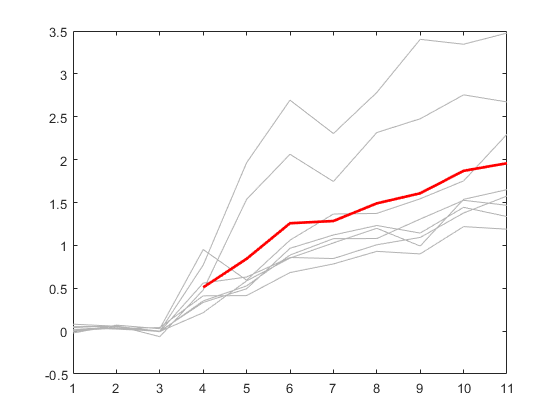

plot([cko4.numLevels:-1:1],cko4.mean,'r','LineWidth',2)

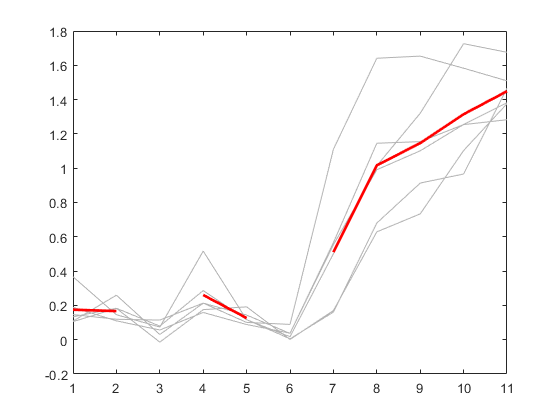


figure;
for x = 1:cko5.numROI
    plot([cko5.numLevels:-1:1],[cko5.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko5.numLevels
    cko5.mean(y) = mean([cko5.ROIdF(y,:).max]);
    cko5.meanfull(y) = mean([cko5.ROIdF(y,:).max]);
     if cko5.mean(y) < minLevel
        cko5.mean(y) = NaN;
    end
end
plot([cko5.numLevels:-1:1],cko5.mean,'r','LineWidth',2)

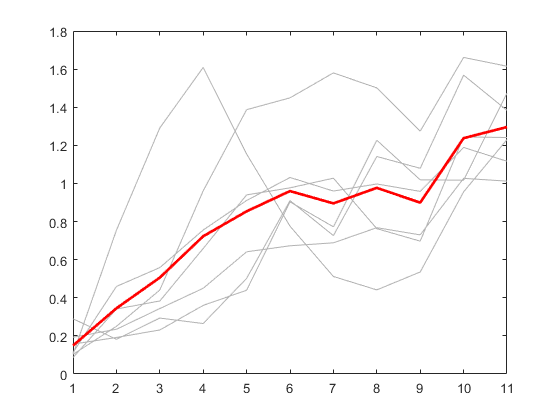


figure;
for x = 1:cko6.numROI
    plot([cko6.numLevels:-1:1],[cko6.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko6.numLevels
    cko6.mean(y) = mean([cko6.ROIdF(y,:).max]);
    cko6.meanfull(y) = mean([cko6.ROIdF(y,:).max]);
     if cko6.mean(y) < minLevel
        cko6.mean(y) = NaN;
    end
end
plot([cko6.numLevels:-1:1],cko6.mean,'r','LineWidth',2)

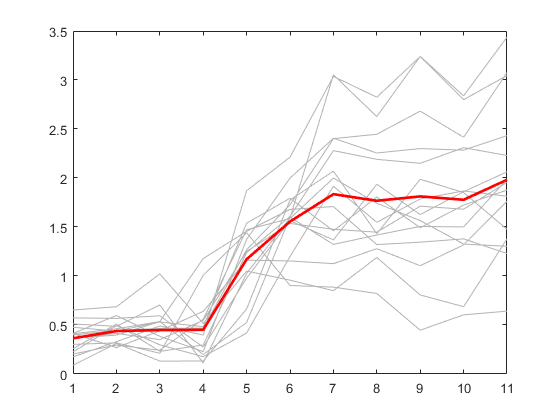


figure;
for x = 1:cko7.numROI
    plot([cko7.numLevels:-1:1],[cko7.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko7.numLevels
    cko7.mean(y) = mean([cko7.ROIdF(y,:).max]);
    cko7.meanfull(y) = mean([cko7.ROIdF(y,:).max]);
     if cko7.mean(y) < minLevel
        cko7.mean(y) = NaN;
    end
end
plot([cko7.numLevels:-1:1],cko7.mean,'r','LineWidth',2)

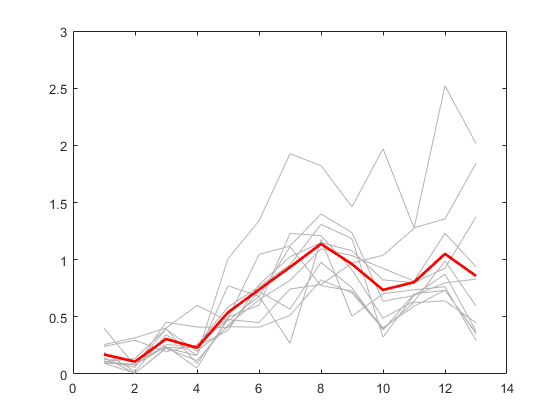

figure;
for x = 1:cko8.numROI
    plot([cko8.numLevels:-1:1],[cko8.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko8.numLevels
    cko8.mean(y) = mean([cko8.ROIdF(y,:).max]);
    cko8.meanfull(y) = mean([cko8.ROIdF(y,:).max]);
     if cko8.mean(y) < minLevel
        cko8.mean(y) = NaN;
    end
end
plot([cko8.numLevels:-1:1],cko8.mean,'r','LineWidth',2)


Ckocells = [cko1.numROI,cko2.numROI,cko3.numROI,cko4.numROI,cko5.numROI,cko6.numROI,cko7.numROI,cko8.numROI];

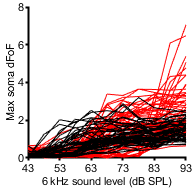


for x = 1:cko1.numROI
    plot([cko1.numLevels:-1:1],[cko1.ROIdF(:,x).max],'Color',[1 0 0],'LineWidth',0.25)
    hold on
end
for x = 1:cko2.numROI
    plot([cko2.numLevels:-1:1],[cko2.ROIdF(:,x).max],'Color',[1 0 0],'LineWidth',0.25)
    hold on
end
for x = 1:cko3.numROI
    plot([cko3.numLevels:-1:1],[cko3.ROIdF(:,x).max],'Color',[1 0 0],'LineWidth',0.25)
    hold on
end
for x = 1:cko4.numROI
    plot([cko4.numLevels:-1:1],[cko4.ROIdF(:,x).max],'Color',[1 0 0],'LineWidth',0.25)
    hold on
end
for x = 1:cko5.numROI
    plot([cko5.numLevels:-1:1],[cko5.ROIdF(:,x).max],'Color',[1 0 0],'LineWidth',0.25)
    hold on
end

for x = 1:cko6.numROI
    plot([cko6.numLevels:-1:1],[cko6.ROIdF(:,x).max],'Color',[1 0 0],'LineWidth',0.25)
    hold on
end

for x = 1:cko7.numROI
    plot([cko7.numLevels:-1:1],[cko7.ROIdF(:,x).max],'Color',[1 0 0],'LineWidth',0.25)
    hold on
end

for x = 1:con1.numROI
    plot([con1.numLevels:-1:1],[con1.ROIdF(:,x).max],'Color','k','LineWidth',0.25)
    hold on
end
for x = 1:con2.numROI
    plot([con2.numLevels:-1:1],[con2.ROIdF(:,x).max],'Color','k','LineWidth',0.25)
    hold on
end
for x = 1:con3.numROI
    plot([con3.numLevels:-1:1],[con3.ROIdF(:,x).max],'Color','k','LineWidth',0.25)
    hold on
end
for x = 1:con4.numROI
    plot([con4.numLevels:-1:1],[con4.ROIdF(:,x).max],'Color','k','LineWidth',0.25)
    hold on
end
for x = 1:con5.numROI
    plot([con5.numLevels:-1:1],[con5.ROIdF(:,x).max],'Color','k','LineWidth',0.25)
    hold on
end
ylabel('Max soma dFoF')
xlabel('6 kHz sound level (dB SPL)')
xticks([1 3 5 7 9 11])
xticklabels({'43','53','63','73','83','93'})
figQuality(gcf,gca,[2 2])
xlim([1 11])
ylim([0 8])

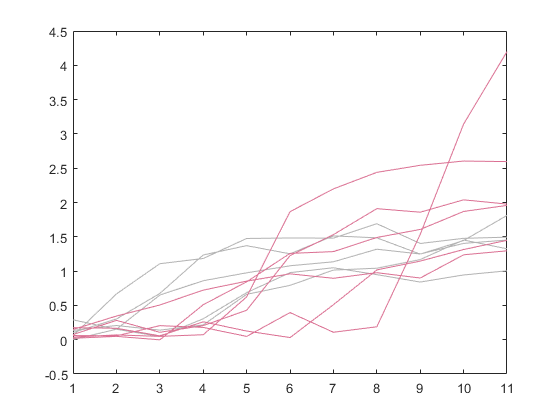


% global mean - control and cKO

figure 
plot([con1.numLevels:-1:1],con1.meanfull,'Color',[0.7 0.7 0.7])
hold on
plot([con2.numLevels:-1:1],con2.meanfull,'Color',[0.7 0.7 0.7])
plot([con3.numLevels:-1:1],con3.meanfull,'Color',[0.7 0.7 0.7])
plot([con4.numLevels:-1:1],con4.meanfull,'Color',[0.7 0.7 0.7])
plot([con5.numLevels:-1:1],con5.meanfull,'Color',[0.7 0.7 0.7])
plot([cko2.numLevels:-1:1],cko1.meanfull,'Color',[219,112,147]/255)
plot([cko2.numLevels:-1:1],cko2.meanfull,'Color',[219,112,147]/255)
plot([cko2.numLevels:-1:1],cko3.meanfull,'Color',[219,112,147]/255)
plot([cko2.numLevels:-1:1],cko4.meanfull,'Color',[219,112,147]/255)
plot([cko2.numLevels:-1:1],cko5.meanfull,'Color',[219,112,147]/255)
plot([cko2.numLevels:-1:1],cko6.meanfull,'Color',[219,112,147]/255)

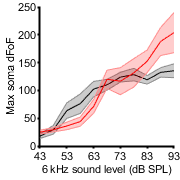

conMeanMatx = [];
for y = 1:con4.numLevels
    con6khzmean(y) = nanmean([con1.mean(y),con2.mean(y),con3.mean(y),con4.mean(y),con5.mean(y),con6.mean(y)]);
    conMeanMatx = [conMeanMatx;[con1.mean(y),con2.mean(y),con3.mean(y),con4.mean(y),con5.mean(y),con6.mean(y)]];
    con6khzSEM(y) = nanstd([con1.mean(y),con2.mean(y),con3.mean(y),con4.mean(y),con5.mean(y),con6.mean(y)])/sqrt(6);
end
tmemMeanMatx = [];
for y = 1:cko3.numLevels
    cko6khzmean(y) = nanmean([cko1.mean(y),cko2.mean(y),cko3.mean(y),cko4.mean(y),cko5.mean(y),cko6.mean(y),cko7.mean(y),cko8.mean(y)]);
    cko6khzSEM(y) = nanstd([cko1.mean(y),cko2.mean(y),cko3.mean(y),cko4.mean(y),cko5.mean(y),cko6.mean(y),cko7.mean(y),cko8.mean(y)])/sqrt(8);
    tmemMeanMatx = [tmemMeanMatx;[cko1.mean(y),cko2.mean(y),cko3.mean(y),cko4.mean(y),cko5.mean(y),cko6.mean(y),cko7.mean(y),cko8.mean(y)]];
end
% plot([con4.numLevels:-1:1],con6khzmean,'k','LineWidth',2)
% plot([con4.numLevels:-1:1],cko6khzmean,'r','LineWidth',2)
figure
shadedErrorBar([con4.numLevels:-1:1],con6khzmean*100,con6khzSEM*100)
hold on
shadedErrorBar([con4.numLevels:-1:1],cko6khzmean*100,cko6khzSEM*100,'lineprops','r')
ylabel('Max soma dFoF')
xlabel('6 kHz sound level (dB SPL)')
xticks([1 3 5 7 9 11])
xticklabels({'43','53','63','73','83','93'})
xlim([1 11])
figQuality(gcf,gca,[1.87 1.87])

%print(gcf,'-dpdf')

% number of responsive neurons/field
figure;
conditions1 = {'Control','cKO'};
ylbl1 = 'Number of responsive cells';
dim1 = [1 2];
[fig5 h p] = compare2(Concells,Ckocells,conditions1,ylbl1,dim1)

fig5 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 26
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = 0.9872

p = 0

ylim([0 20])
p

p = 0

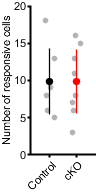


 subP = handleTheSubplot({fig5,fig5},[1 2]);

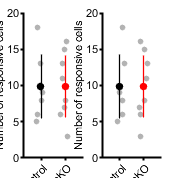

 figQuality(subP,gca,[1.85 1.85])


% mean by cells 
conMax = []


conMax =

     []



j = 1;
numLevels = 11;
for i = 1:con1.numROI
    for k = 1:numLevels
    if [con1.ROIdF(k,i).max] < minLevel
        [con1.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con1.ROIdF(1:numLevels,i).max]';
    j = j + 1;
end
for i = 1:con2.numROI
    for k = 1:numLevels
    if [con2.ROIdF(k,i).max] < minLevel
        [con2.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con2.ROIdF(1:numLevels,i).max]';
    j = j + 1;
end
for i = 1:con3.numROI
    for k = 1:numLevels
    if [con3.ROIdF(k,i).max] < minLevel
        [con3.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con3.ROIdF(1:numLevels,i).max]';
    j = j + 1;
end
 for i = 1:con4.numROI
    for k = 1:numLevels
    if [con4.ROIdF(k,i).max] < minLevel
        [con4.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con4.ROIdF(1:numLevels,i).max]';
    j = j + 1;
 end
 for i = 1:con5.numROI
    for k = 1:numLevels
    if [con5.ROIdF(k,i).max] < minLevel
        [con5.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con5.ROIdF(1:numLevels,i).max]';
    j = j + 1;
 end
 for i = 1:con6.numROI
    for k = 1:numLevels
    if [con6.ROIdF(k,i).max] < minLevel
        [con6.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con6.ROIdF(1:numLevels,i).max]';
    j = j + 1;
 end
 
 % cKO 
 ckoMax = []


ckoMax =

     []



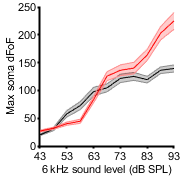

j = 1;
for i = 1:cko1.numROI
    for k = 1:numLevels
    if [cko1.ROIdF(k,i).max] < minLevel
        [cko1.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko1.ROIdF(1:numLevels,i).max]';
    j = j + 1;
end
for i = 1:cko2.numROI
    for k = 1:numLevels
    if [cko2.ROIdF(k,i).max] < minLevel
        [cko2.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko2.ROIdF(1:numLevels,i).max]';
    j = j + 1;
end
for i = 1:cko3.numROI
    for k = 1:numLevels
    if [cko3.ROIdF(k,i).max] < minLevel
        [cko3.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko3.ROIdF(1:numLevels,i).max]';
    j = j + 1;
end
 for i = 1:cko4.numROI
    for k = 1:numLevels
    if [cko4.ROIdF(k,i).max] < minLevel
        [cko4.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko4.ROIdF(1:numLevels,i).max]';
    j = j + 1;
 end
 for i = 1:cko5.numROI
    for k = 1:numLevels
    if [cko5.ROIdF(k,i).max] < minLevel
        [cko5.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko5.ROIdF(1:numLevels,i).max]';
    j = j + 1;
 end
 for i = 1:cko6.numROI
    for k = 1:numLevels
    if [cko6.ROIdF(k,i).max] < minLevel
        [cko6.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko6.ROIdF(1:numLevels,i).max]';
    j = j + 1;
 end
  for i = 1:cko7.numROI
    for k = 1:numLevels
    if [cko7.ROIdF(k,i).max] < minLevel
        [cko7.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko7.ROIdF(1:numLevels,i).max]';
    j = j + 1;
  end
   for i = 1:cko8.numROI-2
    for k = 1:numLevels
    if [cko8.ROIdF(k,i).max] < minLevel
        [cko8.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko8.ROIdF(1:numLevels,i).max]';
    j = j + 1;
 end
 
 con6mean = nanmean(conMax,2);
 con6std = nanstd(conMax,0,2)/sqrt(59);
 
 cko6mean = nanmean(ckoMax,2);
 cko6std = nanstd(ckoMax,0,2)/sqrt(77);
 
figure
shadedErrorBar([con4.numLevels:-1:1],con6mean*100,con6std*100)
hold on
shadedErrorBar([con4.numLevels:-1:1],cko6mean*100,cko6std*100,'lineprops','r')
ylabel('Max soma dFoF')
xlabel('6 kHz sound level (dB SPL)')
xticks([1 3 5 7 9 11])
xticklabels({'43','53','63','73','83','93'})
xlim([1 11])
figQuality(gcf,gca,[1.87 1.87])

%print(gcf,'-dpdf')
 

% LME by mouse (underpowered)
genoBasecon = {'con','con','con','con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'};

geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
mousecon = {'M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6',};
mousecko = {'M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12','M13','M13','M13','M13','M13','M13','M13','M13','M13','M13','M13','M14','M14','M14','M14','M14','M14','M14','M14','M14','M14','M14'};
mouse = [mousecon,mousecko]';
locationBase = {'1' '2','3','4','5','6','7','8','9','10','11'}; 
location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
byMouse = [conMeanMatx(:,1)',conMeanMatx(:,2)',conMeanMatx(:,3)',conMeanMatx(:,4)',conMeanMatx(:,5)',conMeanMatx(:,6)',tmemMeanMatx(:,1)',tmemMeanMatx(:,2)',tmemMeanMatx(:,3)',tmemMeanMatx(:,4)',tmemMeanMatx(:,5)',tmemMeanMatx(:,6)',tmemMeanMatx(:,7)',tmemMeanMatx(:,8)']';

tbl = table(geno,mouse,location,byMouse,'VariableNames',{'Genotype','Mouse','Location','BW'})

tbl = 154×4 table
    Genotype    Mouse     Location      BW   
    ________    ______    ________    _______

    {'con'}     {'M1'}     {'1' }      1.3246
    {'con'}     {'M1'}     {'2' }      1.4538
    {'con'}     {'M1'}     {'3' }      1.1683
    {'con'}     {'M1'}     {'4' }      1.0421
    {'con'}     {'M1'}     {'5' }      1.0149
    {'con'}     {'M1'}     {'6' }     0.79183
    {'con'}     {'M1'}     {'7' }     0.66147
    {'con'}     {'M1'}     {'8' }     0.21546
    {'con'}     {'M1'}     {'9' }     0.13932
    {'con'}     {'M1'}     {'10'}     0.20693
    {'con'}     {'M1'}     {'11'}       0.136
    {'con'}     {'M2'}     {'1' }      1.8121
    {'con'}     {'M2'}     {'2' }      1.4452
    {'con'}     {'M2'}     {'3' }       1.248
    {'con'}     {'M2'}     {'4' }      1.4849
    {'con'}     {'M2'}     {'5' }      1.5133


lme = fitlme(tbl,'BW~Genotype+(1|Location)+(1|Mouse)') 

lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             137
    Fixed effects coefficients           2
    Random effects coefficients         25
    Covariance parameters                3

Formula:
    BW ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    213.21    227.81    -101.6           203.21  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF     pValue       Lower       Upper 
    {'(Intercept)' }        0.94424     0.18534     5.0947    135    1.153e-06      0.5777    1.3108
    {'Genotype_cko'}        0.12019      0.1607    0.74793    135       0.4558    -0.19762     0.438

Random effects covariance parameters (95% CIs):
Group: Location (11 Levels)
    Name1                  Name2                  Type    


% LME model, by cell
locationBase = {'1' '2','3','4','5','6','7','8','9','10','11'}; 
genoBasecon = {'con','con','con','con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'};
mouse1 = {'M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M1'};
mouse2 = {'M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2'};
mouse3 = {'M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3'};
mouse4 = {'M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4'};
mouse5 = {'M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5'};
mouse6 = {'M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6'};
mouse7 = {'M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7'};
mouse8 = {'M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8'};
mouse9 = {'M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9'};
mouse10 = {'M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10'};
mouse11 = {'M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11'};
mouse12 = {'M12','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12'};
mouse13 = {'M13','M13','M13','M13','M13','M13','M13','M13','M13','M13','M13'};
mouse14 = {'M14','M14','M14','M14','M14','M14','M14','M14','M14','M14','M14'};

mouse1con = [mouse1,mouse1,mouse1,mouse1,mouse1,mouse1,mouse1,mouse1,mouse1,mouse1,mouse1,mouse1,mouse1,mouse1,mouse1,mouse1,mouse1,mouse1];
mouse2con = [mouse2,mouse2,mouse2,mouse2,mouse2,mouse2,mouse2,mouse2,mouse2,mouse2,mouse2,mouse2,mouse2];
mouse3con = [mouse3,mouse3,mouse3,mouse3,mouse3,mouse3];
mouse4con = [mouse4,mouse4,mouse4,mouse4,mouse4,mouse4,mouse4,mouse4,mouse4];
mouse5con = [mouse5,mouse5,mouse5,mouse5,mouse5];
mouse6con = [mouse6,mouse6,mouse6,mouse6,mouse6,mouse6,mouse6,mouse6];
mousecon = [mouse1con,mouse2con,mouse3con,mouse4con,mouse5con,mouse6con];

mouse1cko = [mouse7,mouse7,mouse7];
mouse2cko = [mouse8,mouse8,mouse8,mouse8,mouse8,mouse8,mouse8,mouse8,mouse8,mouse8,mouse8,mouse8,mouse8];
mouse3cko = [mouse9,mouse9,mouse9,mouse9,mouse9,mouse9,mouse9,mouse9,mouse9,mouse9,mouse9,mouse9,mouse9,mouse9,mouse9];
mouse4cko = [mouse10,mouse10,mouse10,mouse10,mouse10,mouse10,mouse10,mouse10];
mouse5cko = [mouse11,mouse11,mouse11,mouse11,mouse11,mouse11];
mouse6cko = [mouse12,mouse12,mouse12,mouse12,mouse12,mouse12,mouse12];
mouse7cko = [mouse13,mouse13,mouse13,mouse13,mouse13,mouse13,mouse13,mouse13,mouse13,mouse13,mouse13,mouse13,mouse13,mouse13,mouse13,mouse13];
mouse8cko = [mouse14,mouse14,mouse14,mouse14,mouse14,mouse14,mouse14,mouse14,mouse14];
mousecko = [mouse1cko,mouse2cko,mouse3cko,mouse4cko,mouse5cko,mouse6cko,mouse7cko,mouse8cko];

genocon1 = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon]; % 18 cells  
genocon2 = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon]; % 13 cells
genocon3 = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon]; % 6 cells
genocon4 = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon]; % 9 cells
genocon5 = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon]; % 5 cells
genocon6 = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon]; % 8 cells

genoCon = [genocon1,genocon2,genocon3,genocon4,genocon5,genocon6];

genocko1 = [genoBasecko,genoBasecko,genoBasecko]; % 3 cells
genocko2 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 13 cells
genocko3 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 15 cells
genocko4 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 8 cels
genocko5 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 6 cells
genocko6 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 7 ells
genocko7 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 16 cells
genocko8 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 11 cells

genoCko = [genocko1,genocko2,genocko3,genocko4,genocko5,genocko6,genocko7,genocko8];

loc1con = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
loc2con = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
loc3con = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
loc4con = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
loc5con = [locationBase,locationBase,locationBase,locationBase,locationBase];
loc6con = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];

loccon = [loc1con,loc2con,loc3con,loc4con,loc5con,loc6con];
loc1cko = [locationBase,locationBase,locationBase];
loc2cko = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
loc3cko = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
loc4cko = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
loc5cko = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
loc6cko = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
loc7cko = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
loc8cko = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
loccko = [loc1cko,loc2cko,loc3cko,loc4cko,loc5cko,loc6cko,loc7cko,loc8cko];

loc = [loccon,loccko]';
conVal = reshape(conMax,649,1);
ckoVal = reshape(ckoMax,847,1);
geno = [genoCon,genoCko]';
mouse = [mousecon,mousecko]';

maxVal = [conVal',ckoVal']';
tbl = table(geno,mouse,loc,maxVal,'VariableNames',{'Genotype','Mouse','Location','Max'})

tbl = 1496×4 table
    Genotype    Mouse     Location      Max  
    ________    ______    ________    _______

    {'con'}     {'M1'}     {'1' }      1.8056
    {'con'}     {'M1'}     {'2' }      2.0023
    {'con'}     {'M1'}     {'3' }      1.7688
    {'con'}     {'M1'}     {'4' }      1.9297
    {'con'}     {'M1'}     {'5' }      2.1269
    {'con'}     {'M1'}     {'6' }      2.0108
    {'con'}     {'M1'}     {'7' }      1.7812
    {'con'}     {'M1'}     {'8' }     0.68504
    {'con'}     {'M1'}     {'9' }     0.10158
    {'con'}     {'M1'}     {'10'}     0.10343
    {'con'}     {'M1'}     {'11'}         NaN
    {'con'}     {'M1'}     {'1' }      1.9763
    {'con'}     {'M1'}     {'2' }      1.9429
    {'con'}     {'M1'}     {'3' }      1.8518
    {'con'}     {'M1'}     {'4' }      1.6839
    {'con'}     {'M1'}     {'5' }      1.6694


lme = fitlme(tbl,'Max~Genotype+(1|Location)','FitMethod','reml') 
[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

## whole field 6 kHz

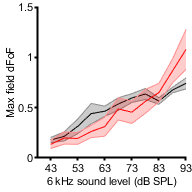


for y = 1:con4.numLevels
    con6khzwholeM(y) = nanmean([con1.WholeF(y).max,con2.WholeF(y).max,con3.WholeF(y).max,con4.WholeF(y).max,con5.WholeF(y).max]);
    con6khzwholeSEM(y) = nanstd([con1.WholeF(y).max,con2.WholeF(y).max,con3.WholeF(y).max,con4.WholeF(y).max,con5.WholeF(y).max])/sqrt(5);
end
for y = 1:cko3.numLevels
    cko6khzwholeM(y) = nanmean([cko1.WholeF(y).max,cko2.WholeF(y).max,cko3.WholeF(y).max,cko4.WholeF(y).max,cko5.WholeF(y).max,cko6.WholeF(y).max,cko7.WholeF(y).max]);
    cko6khzwholeSEM(y) = nanstd([cko1.WholeF(y).max,cko2.WholeF(y).max,cko3.WholeF(y).max,cko4.WholeF(y).max,cko5.WholeF(y).max,cko6.WholeF(y).max,cko7.WholeF(y).max])/sqrt(7);
end

figure
shadedErrorBar([con4.numLevels:-1:1],con6khzwholeM,con6khzwholeSEM)
hold on
shadedErrorBar([con4.numLevels:-1:1],cko6khzwholeM,cko6khzwholeSEM,'lineprops','r')
ylabel('Max field dFoF')
xlabel('6 kHz sound level (dB SPL)')
xticks([1 3 5 7 9 11])
xticklabels({'43','53','63','73','83','93'})
figQuality(gcf,gca,[2 2])

%print(gcf,'-dpdf')




% 9.5 kHz 
con1 = load('C1-exp458 m2 flfl 9_5 khz 4 rep 10-70 db atten 5 db steps R IC 3_ICdata.mat'); %458_2
con1.numLevels = size(con1.ROIdF,1);
con1.numROI = size(con1.ROIdF,2);

con2 = load('C1-exp458 m5 tmem16flfl 9_5 khz 4 rep 5 db steps 10-70 RIC_ICdata.mat'); %458_5
con2.numLevels = size(con2.ROIdF,1);
con2.numROI = size(con2.ROIdF,2);

con3 = load('C1-exp458 m3 flfl 9_5 khz 6 rep 10-60 db atten 5 db steps L IC_ICdata.mat'); %458_3
con3.numLevels = size(con3.ROIdF,1);
con3.numROI = size(con3.ROIdF,2);

con4 = load('C1-20211015 exp467 mouse 1 tmem16flfl 9_5 khz gain 6 rep 10-70 db atten_ICdata.mat'); %458_3
con4.numLevels = size(con4.ROIdF,1);
con4.numROI = size(con4.ROIdF,2);

con5 = load('C1-20211103 exp472 mouse 1 tmem16aflfl 9.5 khz gain 10-70 6 rep_ICdata.mat'); %458_3
con5.numLevels = size(con5.ROIdF,1);
con5.numROI = size(con5.ROIdF,2);

con6 = load('C1-20211217 exp486 mouse 1 tmem16aflfl 9_5 khz gain R IC 10-70 db atten 190deep_ICdata.mat'); 
con6.numLevels = size(con6.ROIdF,1);
con6.numROI = size(con6.ROIdF,2);

minLevel = 0.1;

figure;
for x = 1:con1.numROI
    plot([con1.numLevels:-1:1],[con1.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con1.numLevels
    con1.mean(y) = mean([con1.ROIdF(y,:).max]);
    con1.meanfull(y) = mean([con1.ROIdF(y,:).max]);
     if con1.mean(y) < minLevel
        con1.mean(y) = NaN
    end
end

con1 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [13×5 struct]
        ROIdF: [13×5 struct]
       WholeF: [1×13 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 13
       numROI: 5
         mean: [1.4376 1.2227 1.0187 0.6975 0.9782 0.9437 0.9658 0.8611 0.8573 0.5428 0.2042 0.1827 NaN]
     meanfull: [1.4376 1.2227 1.0187 0.6975 0.9782 0.9437 0.9658 0.8611 0.8573 0.5428 0.2042 0.1827 0.0867]


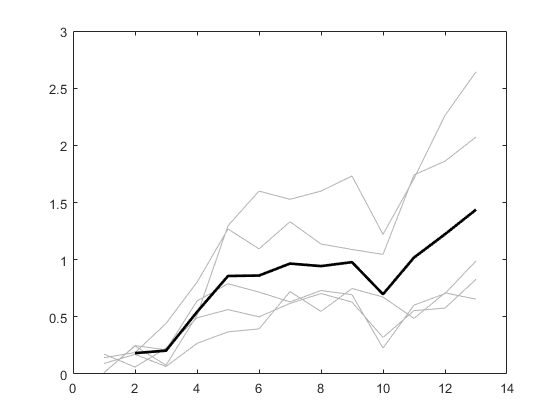

plot([con1.numLevels:-1:1],con1.mean,'k','LineWidth',2)

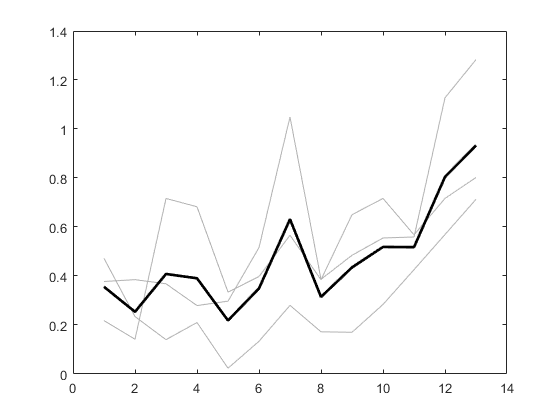


figure;
for x = 1:con2.numROI
    plot([con2.numLevels:-1:1],[con2.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con2.numLevels
    con2.mean(y) = mean([con2.ROIdF(y,:).max]);
    con2.meanfull(y) = mean([con2.ROIdF(y,:).max]);
         if con2.mean(y) < minLevel
        con2.mean(y) = NaN
    end
end
plot([con2.numLevels:-1:1],con2.mean,'k','LineWidth',2)

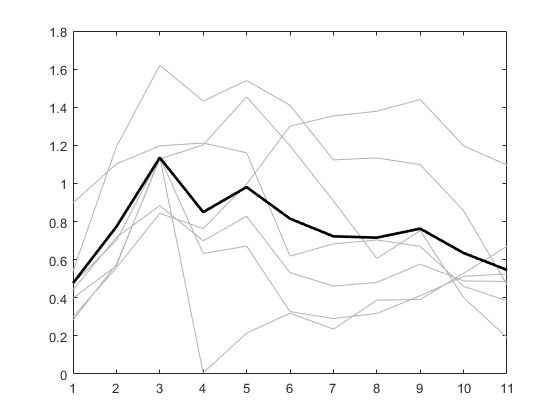


figure;
for x = 1:con3.numROI
    plot([con3.numLevels:-1:1],[con3.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con3.numLevels
    con3.mean(y) = mean([con3.ROIdF(y,:).max]);
    con3.meanfull(y) = mean([con3.ROIdF(y,:).max]);
    if con3.mean(y) < minLevel
        con3.mean(y) = NaN
    end
end
plot([con3.numLevels:-1:1],con3.mean,'k','LineWidth',2)


figure;
for x = 1:con4.numROI
    plot([con4.numLevels:-1:1],[con4.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con4.numLevels
    con4.mean(y) = mean([con4.ROIdF(y,:).max]);
    con4.meanfull(y) = mean([con4.ROIdF(y,:).max]);
    if con4.mean(y) < minLevel
        con4.mean(y) = NaN
    end
end

con4 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [13×6 struct]
        ROIdF: [13×6 struct]
       WholeF: [1×13 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 13
       numROI: 6
         mean: [1.2670 0.7266 0.6020 0.4459 0.4534 0.3199 0.2489 0.2130 0.2962 0.2576 NaN]
     meanfull: [1.2670 0.7266 0.6020 0.4459 0.4534 0.3199 0.2489 0.2130 0.2962 0.2576 0.0948]


con4 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [13×6 struct]
        ROIdF: [13×6 struct]
       WholeF: [1×13 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 13
       numROI: 6
         mean: [1.2670 0.7266 0.6020 0.4459 0.4534 0.3199 0.2489 0.2130 0.2962 0.2576 NaN NaN]
     meanfull: [1.2670 0.7266 0.6020 0.4459 0.4534 0.3199 0.2489 0.2130 0.2962 0.2576 0.0948 0.0420]


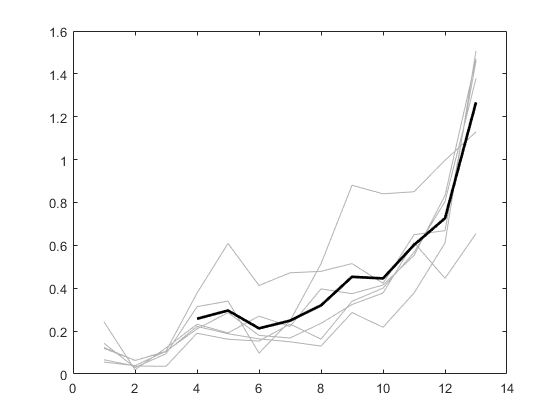

plot([con4.numLevels:-1:1],con4.mean,'k','LineWidth',2)


figure;
for x = 1:con5.numROI
    plot([con5.numLevels:-1:1],[con5.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con5.numLevels
    con5.mean(y) = mean([con5.ROIdF(y,:).max]);
    con5.meanfull(y) = mean([con5.ROIdF(y,:).max]);
    if con5.mean(y) < minLevel
        con5.mean(y) = NaN
    end
end

con5 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [13×4 struct]
        ROIdF: [13×4 struct]
       WholeF: [1×13 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 13
       numROI: 4
         mean: [0.9453 0.6465 0.7825 0.8469 0.8835 1.1656 0.8061 0.5583 0.6484 0.8537 0.2574 0.1206 NaN]
     meanfull: [0.9453 0.6465 0.7825 0.8469 0.8835 1.1656 0.8061 0.5583 0.6484 0.8537 0.2574 0.1206 0.0631]


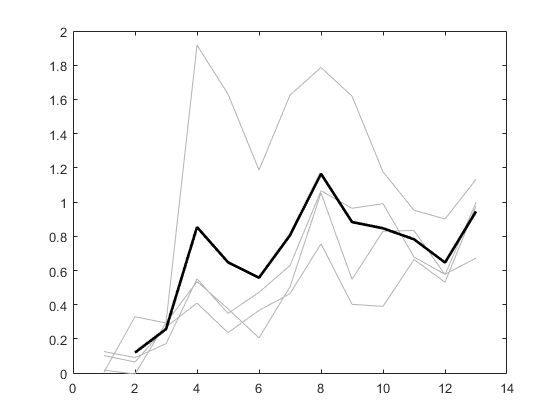

plot([con5.numLevels:-1:1],con5.mean,'k','LineWidth',2)

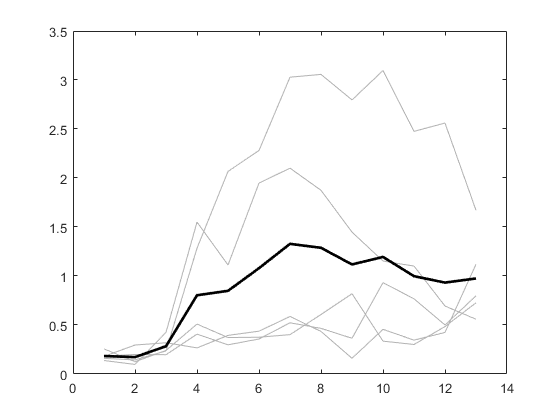



figure;
for x = 1:con6.numROI
    plot([con6.numLevels:-1:1],[con6.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con6.numLevels
    con6.mean(y) = mean([con6.ROIdF(y,:).max]);
    con6.meanfull(y) = mean([con6.ROIdF(y,:).max]);
    if con6.mean(y) < minLevel
        con6.mean(y) = NaN
    end
end
plot([con6.numLevels:-1:1],con6.mean,'k','LineWidth',2)

numCONcells = con1.numROI+con2.numROI+con3.numROI+con4.numROI+con5.numROI+con6.numROI;
Concells = [con1.numROI,con2.numROI,con3.numROI,con4.numROI,con5.numROI,con6.numROI];

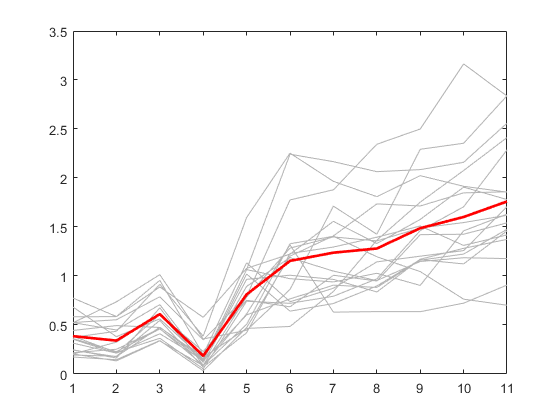



cko1 = load('C1-exp460 mouse5 L IC tecta flfl 9_5 khz 6 rep 10-60 db atten 5 db steps_ICdata.mat'); %460_5
cko1.numLevels = size(cko1.ROIdF,1);
cko1.numROI = size(cko1.ROIdF,2);

cko2 = load('C1-exp458 m1 tecta flfl 9_5 khz 4 rep 10-70 db atten 5 db steps_ICdata.mat'); %458_1
cko2.numLevels = size(cko2.ROIdF,1);
cko2.numROI = size(cko2.ROIdF,2);

cko3 = load('C1-exp456 m2 9_5khz 10-60 db 5 db steps 6 reps 2x later_ICdata.mat'); %456_2
cko3.numLevels = size(cko3.ROIdF,1);
cko3.numROI = size(cko3.ROIdF,2);

cko4 = load('C1-exp460 mouse2 tecta flfl 9_5 khz 4 rep 10-70 db atten 5 db steps_ICdata'); %460_2
cko4.numLevels = size(cko4.ROIdF,1);
cko4.numROI = size(cko4.ROIdF,2);

cko5 = load('C1-20211220 exp487 mouse2 tecta tmem16aflfl 9.5 khz gain 10-70 db atten R IC 170_ICdata.mat'); %460_2
cko5.numLevels = size(cko5.ROIdF,1);
cko5.numROI = size(cko5.ROIdF,2);

cko6 = load('C1-20211229 exp488 mouse 1 tmem16aflfl 9.5 khz gain 10-70db atten 6reps_ICdata.mat'); %460_2
cko6.numLevels = size(cko6.ROIdF,1);
cko6.numROI = size(cko6.ROIdF,2);

minLevel = 0.1;
figure;
for x = 1:cko1.numROI
    plot([cko1.numLevels:-1:1],[cko1.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko1.numLevels
    cko1.mean(y) = mean([cko1.ROIdF(y,:).max]);
    cko1.meanfull(y) = mean([cko1.ROIdF(y,:).max]);
    if cko1.mean(y) < minLevel
        cko1.mean(y) = NaN
    end
end
plot([cko1.numLevels:-1:1],cko1.mean,'r','LineWidth',2)


figure;
for x = 1:cko2.numROI
    plot([cko2.numLevels:-1:1],[cko2.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko2.numLevels
    cko2.mean(y) = mean([cko2.ROIdF(y,:).max]);
    cko2.meanfull(y) = mean([cko2.ROIdF(y,:).max]);
     if cko2.mean(y) < minLevel
        cko2.mean(y) = NaN
    end
end

cko2 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [13×15 struct]
        ROIdF: [13×15 struct]
       WholeF: [1×13 struct]
       allROI: {1×15 cell}
     neuroPil: [256×256 logical]
    numLevels: 13
       numROI: 15
         mean: [2.4709 2.0719 1.9224 1.8289 1.3964 1.1973 0.9135 0.2987 0.2430 0.8860 NaN]
     meanfull: [2.4709 2.0719 1.9224 1.8289 1.3964 1.1973 0.9135 0.2987 0.2430 0.8860 0.0765]


cko2 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [13×15 struct]
        ROIdF: [13×15 struct]
       WholeF: [1×13 struct]
       allROI: {1×15 cell}
     neuroPil: [256×256 logical]
    numLevels: 13
       numROI: 15
         mean: [2.4709 2.0719 1.9224 1.8289 1.3964 1.1973 0.9135 0.2987 0.2430 0.8860 NaN NaN]
     meanfull: [2.4709 2.0719 1.9224 1.8289 1.3964 1.1973 0.9135 0.2987 0.2430 0.8860 0.0765 0.0138]


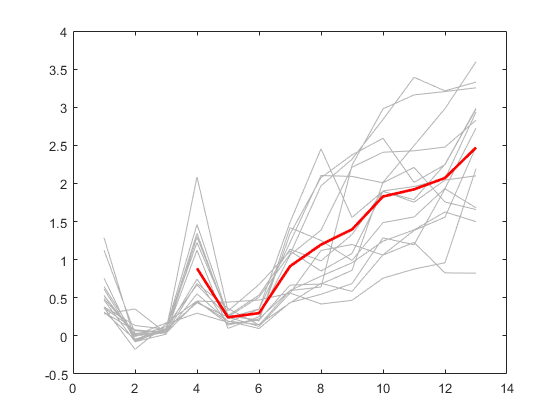

plot([cko2.numLevels:-1:1],cko2.mean,'r','LineWidth',2)

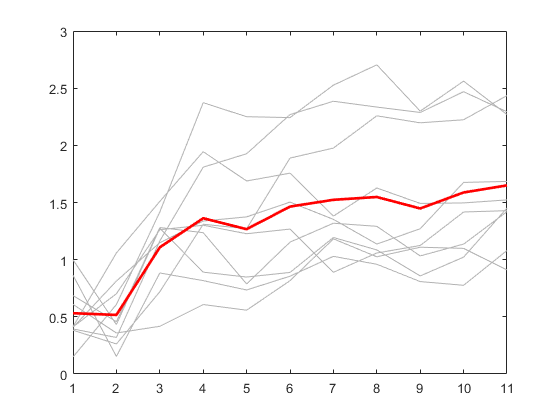


figure;
for x = 1:cko3.numROI
    plot([cko3.numLevels:-1:1],[cko3.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko3.numLevels
    cko3.mean(y) = mean([cko3.ROIdF(y,:).max]);
    cko3.meanfull(y) = mean([cko3.ROIdF(y,:).max]);
     if cko3.mean(y) < minLevel
        cko3.mean(y) = NaN
    end
end
plot([cko3.numLevels:-1:1],cko3.mean,'r','LineWidth',2)


figure;
for x = 1:cko4.numROI
    plot([cko4.numLevels:-1:1],[cko4.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko4.numLevels
    cko4.mean(y) = mean([cko4.ROIdF(y,:).max]);
    cko4.meanfull(y) = mean([cko4.ROIdF(y,:).max]);
     if cko4.mean(y) < minLevel
        cko4.mean(y) = NaN
    end
end

cko4 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [13×9 struct]
        ROIdF: [13×9 struct]
       WholeF: [1×13 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 13
       numROI: 9
         mean: [0.8215 0.8867 0.7344 0.8308 0.7411 0.7107 0.8206 0.6504 0.3891 NaN]
     meanfull: [0.8215 0.8867 0.7344 0.8308 0.7411 0.7107 0.8206 0.6504 0.3891 0.0799]


cko4 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [13×9 struct]
        ROIdF: [13×9 struct]
       WholeF: [1×13 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 13
       numROI: 9
         mean: [0.8215 0.8867 0.7344 0.8308 0.7411 0.7107 0.8206 0.6504 0.3891 NaN NaN]
     meanfull: [0.8215 0.8867 0.7344 0.8308 0.7411 0.7107 0.8206 0.6504 0.3891 0.0799 0.0683]


cko4 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [13×9 struct]
        ROIdF: [13×9 struct]
       WholeF: [1×13 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 13
       numROI: 9
         mean: [0.8215 0.8867 0.7344 0.8308 0.7411 0.7107 0.8206 0.6504 0.3891 NaN NaN NaN]
     meanfull: [0.8215 0.8867 0.7344 0.8308 0.7411 0.7107 0.8206 0.6504 0.3891 0.0799 0.0683 0.0828]


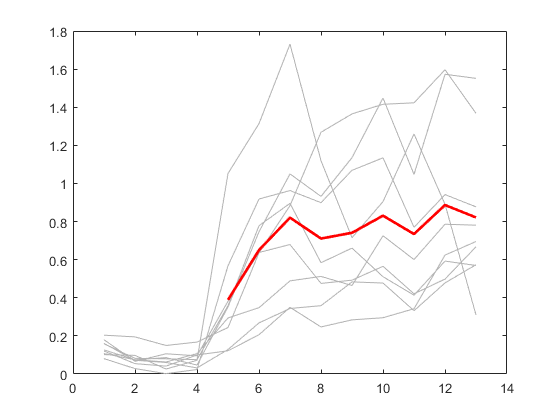

plot([cko4.numLevels:-1:1],cko4.mean,'r','LineWidth',2)


figure;
for x = 1:cko5.numROI
    plot([cko5.numLevels:-1:1],[cko5.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko5.numLevels
    cko5.mean(y) = mean([cko5.ROIdF(y,:).max]);
    cko5.meanfull(y) = mean([cko5.ROIdF(y,:).max]);
     if cko5.mean(y) < minLevel
        cko5.mean(y) = NaN
    end
end

cko5 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [13×14 struct]
        ROIdF: [13×14 struct]
       WholeF: [1×13 struct]
       allROI: {1×14 cell}
     neuroPil: [256×256 logical]
    numLevels: 13
       numROI: 14
         mean: [1.8403 1.7973 1.7996 1.6724 1.6128 1.4398 1.1770 0.5987 0.2054 0.2077 NaN]
     meanfull: [1.8403 1.7973 1.7996 1.6724 1.6128 1.4398 1.1770 0.5987 0.2054 0.2077 0.0655]


cko5 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [13×14 struct]
        ROIdF: [13×14 struct]
       WholeF: [1×13 struct]
       allROI: {1×14 cell}
     neuroPil: [256×256 logical]
    numLevels: 13
       numROI: 14
         mean: [1.8403 1.7973 1.7996 1.6724 1.6128 1.4398 1.1770 0.5987 0.2054 0.2077 NaN NaN]
     meanfull: [1.8403 1.7973 1.7996 1.6724 1.6128 1.4398 1.1770 0.5987 0.2054 0.2077 0.0655 0.0462]


cko5 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [13×14 struct]
        ROIdF: [13×14 struct]
       WholeF: [1×13 struct]
       allROI: {1×14 cell}
     neuroPil: [256×256 logical]
    numLevels: 13
       numROI: 14
         mean: [1.8403 1.7973 1.7996 1.6724 1.6128 1.4398 1.1770 0.5987 0.2054 0.2077 NaN NaN NaN]
     meanfull: [1.8403 1.7973 1.7996 1.6724 1.6128 1.4398 1.1770 0.5987 0.2054 0.2077 0.0655 0.0462 0.0297]


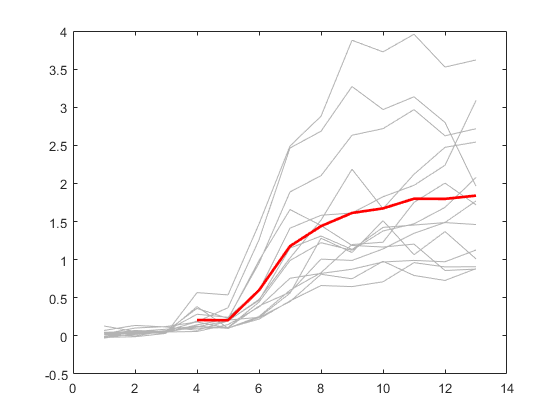

plot([cko5.numLevels:-1:1],cko5.mean,'r','LineWidth',2)

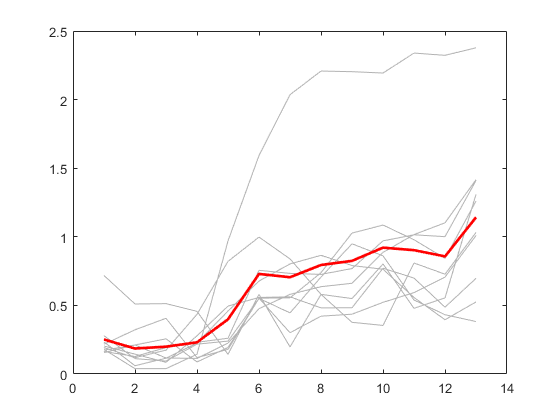


figure;
for x = 1:cko6.numROI
    plot([cko6.numLevels:-1:1],[cko6.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko6.numLevels
    cko6.mean(y) = mean([cko6.ROIdF(y,:).max]);
    cko6.meanfull(y) = mean([cko6.ROIdF(y,:).max]);
     if cko6.mean(y) < minLevel
        cko6.mean(y) = NaN
    end
end
plot([cko6.numLevels:-1:1],cko6.mean,'r','LineWidth',2)

numCKOcells = cko1.numROI+cko2.numROI+cko3.numROI+cko4.numROI+cko5.numROI+cko6.numROI;
Ckocells = [cko1.numROI,cko2.numROI,cko3.numROI,cko4.numROI,cko5.numROI,cko6.numROI];


% traces of all cells
minLevel = 0.1;
conMax = []


conMax =

     []



j = 1;
numLevels = 11;
for i = 1:con1.numROI
    for k = 1:numLevels
    if [con1.ROIdF(k,i).max] < minLevel
        [con1.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con1.ROIdF(1:numLevels,i).max]';
    j = j + 1;
end
for i = 1:con2.numROI
    for k = 1:numLevels
    if [con2.ROIdF(k,i).max] < minLevel
        [con2.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con2.ROIdF(1:numLevels,i).max]';
    j = j + 1;
end
for i = 1:con3.numROI
    for k = 1:numLevels
    if [con3.ROIdF(k,i).max] < minLevel
        [con3.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con3.ROIdF(1:numLevels,i).max]';
    j = j + 1;
end
 for i = 1:con4.numROI
    for k = 1:con4.numLevels
    if [con4.ROIdF(k,i).max] < minLevel
        [con4.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con4.ROIdF(1:numLevels,i).max]';
    j = j + 1;
 end
 for i = 1:con5.numROI
    for k = 1:con5.numLevels
    if [con5.ROIdF(k,i).max] < minLevel
        [con5.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con5.ROIdF(1:numLevels,i).max]';
    j = j + 1;
 end
 for i = 1:con6.numROI
    for k = 1:con6.numLevels
    if [con6.ROIdF(k,i).max] < minLevel
        [con6.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con6.ROIdF(1:numLevels,i).max]';
    j = j + 1;
 end
 
 % cKO 
 ckoMax = []


ckoMax =

     []



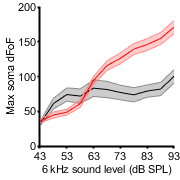

j = 1;
for i = 1:cko1.numROI
    for k = 1:numLevels
    if [cko1.ROIdF(k,i).max] < minLevel
        [cko1.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko1.ROIdF(1:numLevels,i).max]';
    j = j + 1;
end
for i = 1:cko2.numROI
    for k = 1:numLevels
    if [cko2.ROIdF(k,i).max] < minLevel
        [cko2.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko2.ROIdF(1:numLevels,i).max]';
    j = j + 1;
end
for i = 1:cko3.numROI
    for k = 1:numLevels
    if [cko3.ROIdF(k,i).max] < minLevel
        [cko3.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko3.ROIdF(1:numLevels,i).max]';
    j = j + 1;
end
 for i = 1:cko4.numROI
    for k = 1:numLevels
    if [cko4.ROIdF(k,i).max] < minLevel
        [cko4.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko4.ROIdF(1:numLevels,i).max]';
    j = j + 1;
 end
 for i = 1:cko5.numROI
    for k = 1:numLevels
    if [cko5.ROIdF(k,i).max] < minLevel
        [cko5.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko5.ROIdF(1:numLevels,i).max]';
    j = j + 1;
 end
 for i = 1:cko6.numROI
    for k = 1:numLevels
    if [cko6.ROIdF(k,i).max] < minLevel
        [cko6.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko6.ROIdF(1:numLevels,i).max]';
    j = j + 1;
 end

 con95mean = nanmean(conMax,2);
 con95std = nanstd(conMax,0,2)/sqrt(30);
 
 cko95mean = nanmean(ckoMax,2);
 cko95std = nanstd(ckoMax,0,2)/sqrt(77);
 
figure
shadedErrorBar([numLevels:-1:1],con95mean*100,con95std*100)
hold on
shadedErrorBar([numLevels:-1:1],cko95mean*100,cko95std*100,'lineprops','r')
ylabel('Max soma dFoF')
xlabel('6 kHz sound level (dB SPL)')
xticks([1 3 5 7 9 11])
xticklabels({'43','53','63','73','83','93'})
xlim([1 11])
figQuality(gcf,gca,[1.87 1.87])

%print(gcf,'-dpdf')


% lme model by cell 
locationBase = {'1' '2','3','4','5','6','7','8','9','10','11'}; 
genoBasecon = {'con','con','con','con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'};
mouse1Basecon = {'M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M1'};
mouse2Basecon = {'M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2'};
mouse3Basecon = {'M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3'};
mouse4Basecon = {'M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4'};
mouse5Basecon = {'M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5'};
mouse6Basecon = {'M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6'};
mouse7Basecon = {'M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7'};
mouse8Basecon = {'M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8'};
mouse9Basecon = {'M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9'};
mouse10Basecon = {'M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10'};
mouse11Basecon = {'M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11'};
mouse12Basecon = {'M12','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12'};

mouse1 = [mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon];
mouse2 = [mouse2Basecon,mouse2Basecon,mouse2Basecon];
mouse3 = [mouse3Basecon,mouse3Basecon,mouse3Basecon,mouse3Basecon,mouse3Basecon,mouse3Basecon,mouse3Basecon];
mouse4 = [mouse4Basecon,mouse4Basecon,mouse4Basecon,mouse4Basecon,mouse4Basecon,mouse4Basecon];
mouse5 = [mouse5Basecon,mouse5Basecon,mouse5Basecon,mouse5Basecon];
mouse6 = [mouse6Basecon,mouse6Basecon,mouse6Basecon,mouse6Basecon,mouse6Basecon];
mouseCon = [mouse1,mouse2,mouse3,mouse4,mouse5,mouse6];
mouse7 = [mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon];
mouse8 = [mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon]

mouse8 = 1×165 cell array
    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    {'M8'}    

mouse9 = [mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon];
mouse10 = [mouse10Basecon,mouse10Basecon,mouse10Basecon,mouse10Basecon,mouse10Basecon,mouse10Basecon,mouse10Basecon,mouse10Basecon,mouse10Basecon];
mouse11 = [mouse11Basecon,mouse11Basecon,mouse11Basecon,mouse11Basecon,mouse11Basecon,mouse11Basecon,mouse11Basecon,mouse11Basecon,mouse11Basecon,mouse11Basecon,mouse11Basecon,mouse11Basecon,mouse11Basecon,mouse11Basecon,];
mouse12 = [mouse12Basecon,mouse12Basecon,mouse12Basecon,mouse12Basecon,mouse12Basecon,mouse12Basecon,mouse12Basecon,mouse12Basecon,mouse12Basecon,mouse12Basecon];
mouseCko = [mouse7,mouse8,mouse9,mouse10,mouse11,mouse12];

genoCon1 = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon]; % 5 cells
genoCon2 = [genoBasecon,genoBasecon,genoBasecon]; % 3 cells
genoCon3 = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon]; % 7 cells
genoCon4 = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon]; % 6 cells
genoCon5 = [genoBasecon,genoBasecon,genoBasecon,genoBasecon]; %4 cells
genoCon6 = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon]; % 5 cells
genoCon = [genoCon1,genoCon2,genoCon3,genoCon4,genoCon5,genoCon6];

genocko1 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 19 cells
genocko2 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 15 cells
genocko3 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 10 cells
genocko4 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 9 cells
genocko5 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 14 cells
genocko6 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 10 cells

genoCko = [genocko1,genocko2,genocko3,genocko4,genocko5,genocko6];

locationCon1 = [locationBase,locationBase,locationBase,locationBase,locationBase];
locationCon2 = [locationBase,locationBase,locationBase];
locationCon3 = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
locationCon4 = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
locationCon5 = [locationBase,locationBase,locationBase,locationBase];
locationCon6 = [locationBase,locationBase,locationBase,locationBase,locationBase];

locCon = [locationCon1,locationCon2,locationCon3,locationCon4,locationCon5,locationCon6];

locationCko1 = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
locationCko2 = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
locationCko3 = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
locationCko4 = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
locationCko5 = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
locationCko6 = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
locCko = [locationCko1,locationCko2,locationCko3,locationCko4,locationCko5,locationCko6];

mouse = [mouseCon,mouseCko]';
geno = [genoCon,genoCko]';
loc = [locCon,locCko]';
conMaxVal = reshape(conMax,330,1);
ckoMaxVal = reshape(ckoMax,847,1);
maxVal = [conMaxVal',ckoMaxVal']';

tbl = table(geno,mouse,loc,maxVal,'VariableNames',{'Genotype','Mouse','Location','Max'})

tbl = 1177×4 table
    Genotype    Mouse     Location      Max  
    ________    ______    ________    _______

    {'con'}     {'M1'}     {'1' }      2.6429
    {'con'}     {'M1'}     {'2' }      2.2621
    {'con'}     {'M1'}     {'3' }      1.7096
    {'con'}     {'M1'}     {'4' }      1.2211
    {'con'}     {'M1'}     {'5' }      1.7316
    {'con'}     {'M1'}     {'6' }      1.5998
    {'con'}     {'M1'}     {'7' }      1.5279
    {'con'}     {'M1'}     {'8' }      1.5996
    {'con'}     {'M1'}     {'9' }      1.2972
    {'con'}     {'M1'}     {'10'}     0.51343
    {'con'}     {'M1'}     {'11'}         NaN
    {'con'}     {'M1'}     {'1' }      2.0729
    {'con'}     {'M1'}     {'2' }      1.8615
    {'con'}     {'M1'}     {'3' }      1.7413
    {'con'}     {'M1'}     {'4' }      1.0463
    {'con'}     {'M1'}     {'5' }      1.0891


lme = fitlme(tbl,'Max~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml') 

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations            1118
    Fixed effects coefficients           2
    Random effects coefficients         23
    Covariance parameters                3

Formula:
    Max ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2010.8    2035.9    -1000.4          2000.8  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat     DF      pValue        Lower         Upper  
    {'(Intercept)' }        0.72867     0.15574    4.6788    1116    3.2392e-06        0.4231     1.0342
    {'Genotype_cko'}         0.2821     0.14689    1.9204    1116      0.055058    -0.0061191    0.57031

Random effects covariance parameters (95% CIs):
Group: Location (11 Levels)
    Name1                  Name2           

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta =     0.7287
    0.2821


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE         tStat     DF        pValue        Lower        Upper  
    {'(Intercept)' }        0.72867     0.15574    4.6788    19.799    0.00014794      0.40359     1.0538
    {'Genotype_cko'}         0.2821     0.14689    1.9204      10.1       0.08346    -0.044762    0.60895


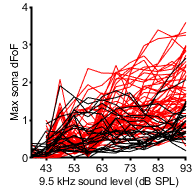


% plot all cells, control and cKO


for x = 1:cko1.numROI
    plot([cko1.numLevels+2:-1:3],[cko1.ROIdF(:,x).max],'Color',[1 0 0],'LineWidth',0.25)
    hold on
end
for x = 1:cko2.numROI
    plot([cko2.numLevels:-1:1],[cko2.ROIdF(:,x).max],'Color',[1 0 0],'LineWidth',0.25)
    hold on
end
for x = 1:cko3.numROI
    plot([cko3.numLevels+2:-1:3],[cko3.ROIdF(:,x).max],'Color',[1 0 0],'LineWidth',0.25)
    hold on
end
for x = 1:cko4.numROI
    plot([cko4.numLevels:-1:1],[cko4.ROIdF(:,x).max],'Color',[1 0 0],'LineWidth',0.25)
    hold on
end

for x = 1:con1.numROI
    plot([con1.numLevels:-1:1],[con1.ROIdF(:,x).max],'Color','k','LineWidth',0.25)
    hold on
end
for x = 1:con2.numROI
    plot([con2.numLevels:-1:1],[con2.ROIdF(:,x).max],'Color','k','LineWidth',0.25)
    hold on
end
for x = 1:con3.numROI
    plot([con3.numLevels+2:-1:3],[con3.ROIdF(:,x).max],'Color','k','LineWidth',0.25)
    hold on
end
for x = 1:con4.numROI
    plot([con4.numLevels:-1:1],[con4.ROIdF(:,x).max],'Color','k','LineWidth',0.25)
    hold on
end
for x = 1:con5.numROI
    plot([con5.numLevels:-1:1],[con5.ROIdF(:,x).max],'Color','k','LineWidth',0.25)
    hold on
end
ylabel('Max soma dFoF')
xlabel('9.5 kHz sound level (dB SPL)')
xticks([1 3 5 7 9 11 13])
xticklabels({'33','43','53','63','73','83','93'})
figQuality(gcf,gca,[2 2])
xlim([2 13])
ylim([0 4])

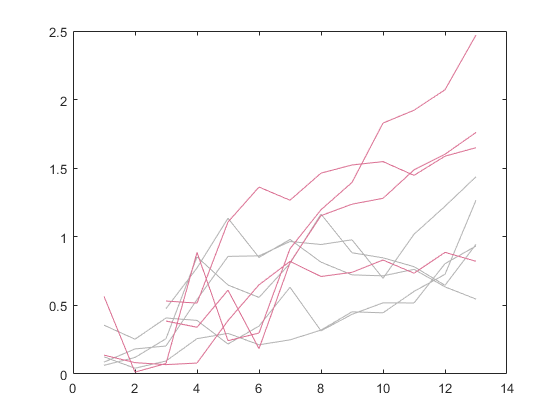


figure 
plot([con1.numLevels:-1:1],con1.meanfull,'Color',[0.7 0.7 0.7])
hold on
plot([con2.numLevels:-1:1],con2.meanfull,'Color',[0.7 0.7 0.7])
plot([con3.numLevels+2:-1:3],con3.meanfull,'Color',[0.7 0.7 0.7])
plot([con4.numLevels:-1:1],con4.meanfull,'Color',[0.7 0.7 0.7])
plot([con5.numLevels:-1:1],con5.meanfull,'Color',[0.7 0.7 0.7])
plot([cko1.numLevels+2:-1:3],cko1.meanfull,'Color',[219,112,147]/255)
plot([cko2.numLevels:-1:1],cko2.meanfull,'Color',[219,112,147]/255)
plot([cko3.numLevels+2:-1:3],cko3.meanfull,'Color',[219,112,147]/255)
plot([cko4.numLevels:-1:1],cko4.meanfull,'Color',[219,112,147]/255)

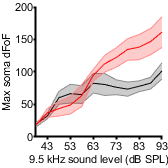



% SEM by animal (mean of means
conMeanMatx = [];
for y = 1:con2.numLevels-2
    con9khzmean(y) = nanmean([con1.mean(y),con2.mean(y),con3.mean(y),con4.mean(y),con5.mean(y),con6.mean(y)]);
    conMeanMatx = [conMeanMatx;[con1.mean(y),con2.mean(y),con3.mean(y),con4.mean(y),con5.mean(y),con6.mean(y)]];
    con9khzSEM(y) = nanstd([con1.mean(y),con2.mean(y),con3.mean(y),con4.mean(y),con5.mean(y),con6.mean(y)])/sqrt(6);
end
for y = 12:13
    con9khzmean(y) = nanmean([con1.mean(y),con2.mean(y),con4.mean(y),con5.mean(y)]);
    conMeanMatx = [conMeanMatx;[con1.mean(y),con2.mean(y),NaN,con4.mean(y),con5.mean(y),NaN]];
    con9khzSEM(y) = nanstd([con1.mean(y),con2.mean(y),con4.mean(y),con5.mean(y)])/sqrt(5);
end
ckoMeanMatx = [];
for y = 1:cko3.numLevels
    cko9khzmean(y) = nanmean([cko1.mean(y),cko2.mean(y),cko3.mean(y),cko4.mean(y),cko5.mean(y),cko6.mean(y)]);
    ckoMeanMatx = [ckoMeanMatx;[cko1.mean(y),cko2.mean(y),cko3.mean(y),cko4.mean(y),cko5.mean(y),cko6.mean(y)]];
    cko9khzSEM(y) = nanstd([cko1.mean(y),cko2.mean(y),cko3.mean(y),cko4.mean(y),cko5.mean(y),cko6.mean(y)])/sqrt(6);   
end
for y = 12:13
    cko9khzmean(y) = nanmean([cko2.mean(y),cko4.mean(y),cko5.mean(y),cko6.mean(y)]);
    ckoMeanMatx = [ckoMeanMatx;[NaN,cko2.mean(y),NaN,cko4.mean(y),cko5.mean(y),cko6.mean(y)]];
    cko9khzSEM(y) = nanstd([cko2.mean(y),cko4.mean(y),cko5.mean(y),cko6.mean(y)])/sqrt(4);
end
% plot([con4.numLevels:-1:1],con6khzmean,'k','LineWidth',2)
% plot([con4.numLevels:-1:1],cko6khzmean,'r','LineWidth',2)
figure
shadedErrorBar([con2.numLevels:-1:1],con9khzmean*100,con9khzSEM*100)
hold on
shadedErrorBar([con2.numLevels:-1:1],cko9khzmean*100,cko9khzSEM*100,'lineprops','r')
ylabel('Max soma dFoF')
xlabel('9.5 kHz sound level (dB SPL)')
xticks([1 3 5 7 9 11 13])
xticklabels({'33','43','53','63','73','83','93'})
figQuality(gcf,gca,[1.75 1.75])
xlim([2 13])

%print(gcf,'-dpdf')

% number of responsive neurons/field
figure;
conditions1 = {'Control','cKO'};
ylbl1 = 'Number of responsive cells';
dim1 = [1 2];
[fig5 h p] = compare2(Concells,Ckocells,conditions1,ylbl1,dim1)

fig5 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 68
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = 8.9668e-04

p = 1

ylim([0 20])
p

p = 1

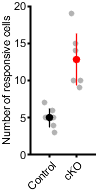


ttest2(Concells,Ckocells,'Vartype','unequal')
 subP = handleTheSubplot({fig5,fig5},[1 2]);

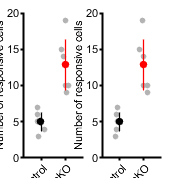

 figQuality(subP,gca,[1.85 1.85])

## whole field analysis

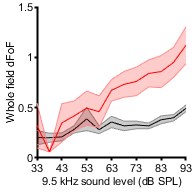

% mean of field during sound-evoked response 
% representative of widefield signal - cell processes and neuropil, takes
% into consideration # of cells responsive, too. Unbiased. 

% 9.5 kHz
for y = 1:con2.numLevels-2
    con9khzwholeM(y) = nanmean([con1.WholeF(y).max,con2.WholeF(y).max,con3.WholeF(y).max,con4.WholeF(y).max,con5.WholeF(y).max]);
    con9khzwholeSEM(y) = nanstd([con1.WholeF(y).max,con2.WholeF(y).max,con3.WholeF(y).max,con4.WholeF(y).max,con5.WholeF(y).max])/sqrt(5);
end
for y = 12:13
    con9khzwholeM(y) = nanmean([con1.WholeF(y).max,con2.WholeF(y).max,con4.WholeF(y).max,con5.WholeF(y).max]);
    con9khzwholeSEM(y) = nanstd([con1.WholeF(y).max,con2.WholeF(y).max,con4.WholeF(y).max,con5.WholeF(y).max])/sqrt(4);
end
for y = 1:cko3.numLevels
    cko9khzwholeM(y) = nanmean([cko1.WholeF(y).max,cko2.WholeF(y).max,cko3.WholeF(y).max,cko4.WholeF(y).max]);
    cko9khzwholeSEM(y) = nanstd([cko1.WholeF(y).max,cko2.WholeF(y).max,cko3.WholeF(y).max,cko4.WholeF(y).max])/sqrt(5);   
end
for y = 12:13
    cko9khzwholeM(y) = nanmean([cko2.WholeF(y).max,cko4.WholeF(y).max]);
    cko9khzwholeSEM(y) = nanstd([cko2.WholeF(y).max,cko4.WholeF(y).max])/sqrt(2);
end

figure
shadedErrorBar([con2.numLevels:-1:1],con9khzwholeM,con9khzwholeSEM)
hold on
shadedErrorBar([con2.numLevels:-1:1],cko9khzwholeM,cko9khzwholeSEM,'lineprops','r')
ylabel('Whole field dFoF')
xlabel('9.5 kHz sound level (dB SPL)')
xticks([1 3 5 7 9 11 13])
xticklabels({'33','43','53','63','73','83','93'})
figQuality(gcf,gca,[2 2])
xlim([1 13])

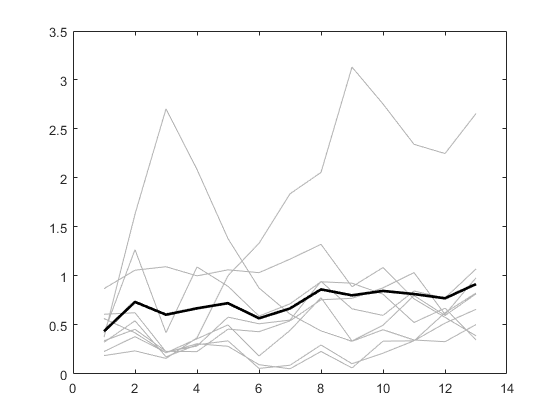

% 12 khz gain - kinda ugly

con1 = load('C1-20211103 exp472 mouse 2 tmem16aflfl 12 khz gain 10-70 6 rep L IC_ICdata.mat');
con1.numLevels = size(con1.ROIdF,1);
con1.numROI = size(con1.ROIdF,2);

con2 = load('C1-20211217 exp486 mouse 1 tmem16aflfl 12 khz gain R IC 10-70 db atten 190deep_ICdata.mat');
con2.numLevels = size(con2.ROIdF,1);
con2.numROI = size(con2.ROIdF,2);

con3 = load('C1-20211220 exp487 mouse1 tmem16aflfl 12 khz gain 10-70 db L IC 150 deep_ICdata.mat');
con3.numLevels = size(con3.ROIdF,1);
con3.numROI = size(con3.ROIdF,2);

cko1 = load('C1-exp456 m2 12khz 10-60 db 5 db steps 6 reps 2x later_ICdata.mat');
cko2 = load('C1-exp458 m1 tecta flfl 12 khz 4 rep 10-70 db atten 5 db steps_ICdata.mat');
cko3 = load('C1-exp460 mouse5 L IC tecta flfl 12 khz 4 rep 10-60 db atten 5 db steps_ICdata.mat');
cko1.numLevels = size(cko1.ROIdF,1);
cko1.numROI = size(cko1.ROIdF,2);
cko2.numLevels = size(cko2.ROIdF,1);
cko2.numROI = size(cko2.ROIdF,2);
cko3.numLevels = size(cko3.ROIdF,1);
cko3.numROI = size(cko3.ROIdF,2);
minLevel = 0.01;

figure;
for x = 1:con1.numROI
    plot([con1.numLevels:-1:1],[con1.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con1.numLevels
    con1.mean(y) = mean([con1.ROIdF(y,:).max]);
    con1.meanfull(y) = mean([con1.ROIdF(y,:).max]);
     if con1.mean(y) < minLevel
        con1.mean(y) = NaN
    end
end
plot([con1.numLevels:-1:1],con1.mean,'k','LineWidth',2)

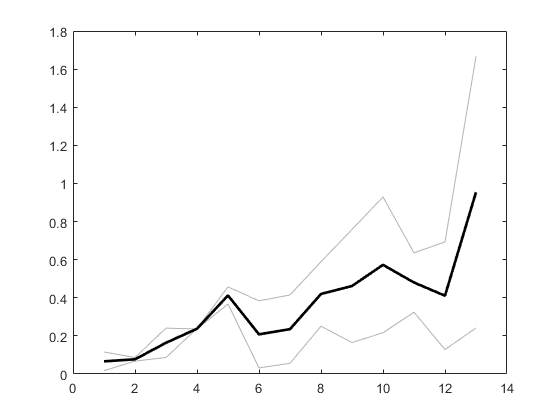


figure;
for x = 1:con2.numROI
    plot([con2.numLevels:-1:1],[con2.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con2.numLevels
    con2.mean(y) = mean([con2.ROIdF(y,:).max]);
    con2.meanfull(y) = mean([con2.ROIdF(y,:).max]);
     if con2.mean(y) < minLevel
        con2.mean(y) = NaN
    end
end
plot([con2.numLevels:-1:1],con2.mean,'k','LineWidth',2)

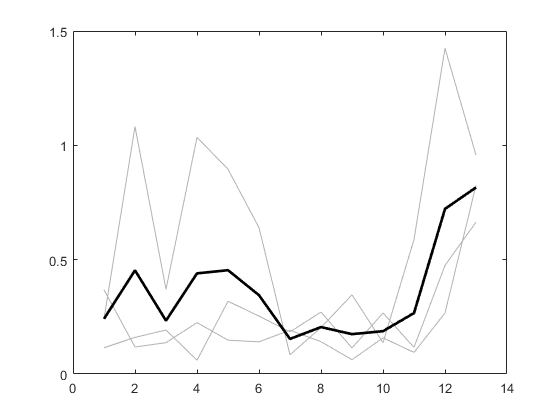


figure;
for x = 1:con3.numROI
    plot([con3.numLevels:-1:1],[con3.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con3.numLevels
    con3.mean(y) = mean([con3.ROIdF(y,:).max]);
    con3.meanfull(y) = mean([con3.ROIdF(y,:).max]);
     if con3.mean(y) < minLevel
        con3.mean(y) = NaN
    end
end
plot([con3.numLevels:-1:1],con3.mean,'k','LineWidth',2)

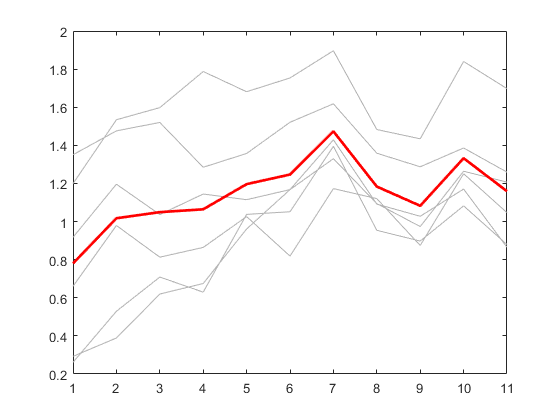



figure;
for x = 1:cko1.numROI
    plot([cko1.numLevels:-1:1],[cko1.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko1.numLevels
    cko1.mean(y) = mean([cko1.ROIdF(y,:).max]);
    cko1.meanfull(y) = mean([cko1.ROIdF(y,:).max]);
    if cko1.mean(y) < minLevel
        cko1.mean(y) = NaN
    end
end
plot([cko1.numLevels:-1:1],cko1.mean,'r','LineWidth',2)

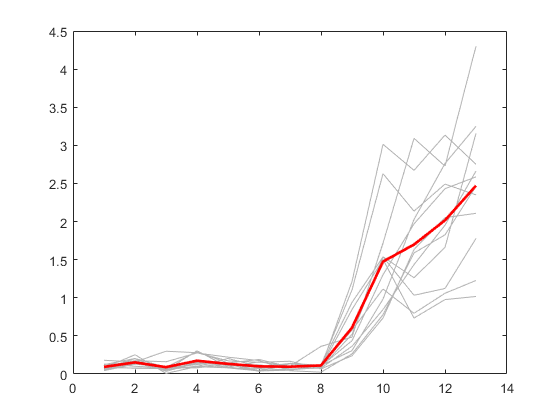


figure;
for x = 1:cko2.numROI
    plot([cko2.numLevels:-1:1],[cko2.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko2.numLevels
    cko2.mean(y) = mean([cko2.ROIdF(y,:).max]);
    cko2.meanfull(y) = mean([cko2.ROIdF(y,:).max]);
     if cko2.mean(y) < minLevel
        cko2.mean(y) = NaN
    end
end
plot([cko2.numLevels:-1:1],cko2.mean,'r','LineWidth',2)

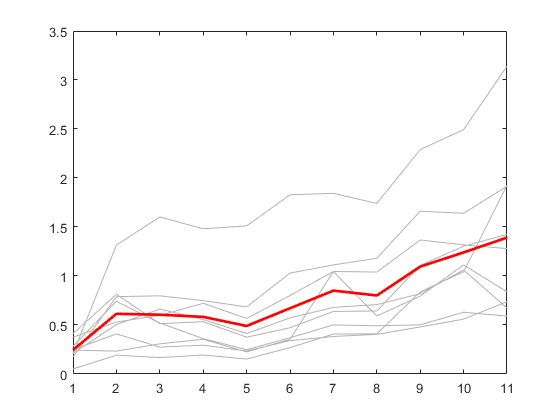


figure;
for x = 1:cko3.numROI
    plot([cko3.numLevels:-1:1],[cko3.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko3.numLevels
    cko3.mean(y) = mean([cko3.ROIdF(y,:).max]);
    cko3.meanfull(y) = mean([cko3.ROIdF(y,:).max]);
     if cko3.mean(y) < minLevel
        cko3.mean(y) = NaN
    end
end
plot([cko3.numLevels:-1:1],cko3.mean,'r','LineWidth',2)

numLevels2 = 11;


conMax = []


conMax =

     []



j = 1;
for i = 1:con1.numROI
    for k = 1:numLevels2
    if [con1.ROIdF(k,i).max] < minLevel
        [con1.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con1.ROIdF(1:numLevels2,i).max]';
    j = j + 1;
end
for i = 1:con2.numROI
    for k = 1:numLevels2
    if [con2.ROIdF(k,i).max] < minLevel
        [con2.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con2.ROIdF(1:numLevels2,i).max]';
    j = j + 1;
end
for i = 1:con3.numROI
    for k = 1:numLevels2
    if [con3.ROIdF(k,i).max] < minLevel
        [con3.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con3.ROIdF(1:numLevels2,i).max]';
    j = j + 1;
end

  % cKO 
 ckoMax = []


ckoMax =

     []



j = 1;
for i = 1:cko1.numROI
    for k = 1:numLevels2
    if [cko1.ROIdF(k,i).max] < minLevel
        [cko1.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko1.ROIdF(1:numLevels2,i).max]';
    j = j + 1;
end
for i = 1:cko2.numROI
    for k = 1:numLevels2
    if [cko2.ROIdF(k,i).max] < minLevel
        [cko2.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko2.ROIdF(1:numLevels2,i).max]';
    j = j + 1;
end
for i = 1:cko3.numROI
    for k = 1:numLevels2
    if [cko3.ROIdF(k,i).max] < minLevel
        [cko3.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko3.ROIdF(1:numLevels2,i).max]';
    j = j + 1;
end

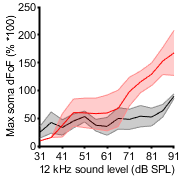

conMeanMatx = [];
ckoMeanMatx = [];

for y = 1:con1.numLevels
    con12khzmean(y) = nanmean([con1.mean(y),con2.mean(y),con3.mean(y)]);
    conMeanMatx = [conMeanMatx;[con1.mean(y),con2.mean(y),con3.mean(y)]];
    con12khzSEM(y) = nanstd([con1.mean(y),con2.mean(y),con3.mean(y)])/sqrt(3);
end

for y = 1:cko3.numLevels
    cko12khzmean(y) = nanmean([cko1.mean(y),cko2.mean(y),cko3.mean(y)]);
    ckoMeanMatx = [ckoMeanMatx;[cko1.mean(y),cko2.mean(y),cko3.mean(y)]];
    cko12khzSEM(y) = nanstd([cko1.mean(y),cko2.mean(y),cko3.mean(y)])/sqrt(3);   
end
for y = 12:13
    cko12khzmean(y) = nanmean([cko2.mean(y)]);
    ckoMeanMatx = [ckoMeanMatx;[NaN,cko2.mean(y),NaN]];
    cko12khzSEM(y) = nanstd([cko2.mean(y)])/sqrt(1);
end



figure
shadedErrorBar([con1.numLevels:-1:1],con12khzmean*100,con12khzSEM*100)
hold on
shadedErrorBar([con1.numLevels:-1:1],cko12khzmean*100,cko12khzSEM*100,'lineprops','r')
ylabel('Max soma dFoF (% *100)')
xlabel('12 kHz sound level (dB SPL)')
xticks([1 3 5 7 9 11 13])
xticklabels({'31','41','51','61','71','81','91'})
xlim([1 13])
ylim([0 250])
figQuality(gcf,gca,[1.87 1.87])

%print(gcf,'-dpdf')


% LME model, by cell
locationBase = {'1' '2','3','4','5','6','7','8','9','10','11'}; 
genoBasecon = {'con','con','con','con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'};
mouse1 = {'M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M1'};
mouse2 = {'M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2'};
mouse3 = {'M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3'};
mouse4 = {'M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4'};
mouse5 = {'M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5'};
mouse6 = {'M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6'};

loc1con = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
loc2con = [locationBase,locationBase];
loc3con = [locationBase,locationBase,locationBase];
loc4cko = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
loc5cko = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
loc6cko = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];

loc = [loc1con,loc2con,loc3con,loc4cko,loc5cko,loc6cko]';
mouse1con = [mouse1,mouse1,mouse1,mouse1,mouse1,mouse1,mouse1,mouse1,mouse1];
mouse2con = [mouse2,mouse2];
mouse3con = [mouse3,mouse3,mouse3];
mouse4cko = [mouse4,mouse4,mouse4,mouse4,mouse4,mouse4];
mouse5cko = [mouse5,mouse5,mouse5,mouse5,mouse5,mouse5,mouse5,mouse5,mouse5,mouse5,mouse5,mouse5];
mouse6cko = [mouse6,mouse6,mouse6,mouse6,mouse6,mouse6,mouse6,mouse6,mouse6];

mouse = [mouse1con,mouse2con,mouse3con,mouse4cko,mouse5cko,mouse6cko]';

genocon1 = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon]; % 9 cells
genocon2 = [genoBasecon,genoBasecon]; % 2 cells
genocon3 = [genoBasecon,genoBasecon,genoBasecon]; % 3 cells

genocko1 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 6 cells
genocko2 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 12 cells
genocko3 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 9 cells

geno = [genocon1,genocon2,genocon3,genocko1,genocko2,genocko3]';

conVal = reshape(conMax,154,1);
ckoVal = reshape(ckoMax,297,1);

maxVal = [conVal',ckoVal']';
tbl = table(geno,mouse,loc,maxVal,'VariableNames',{'Genotype','Mouse','Location','Max'})

tbl = 451×4 table
    Genotype    Mouse     Location      Max  
    ________    ______    ________    _______

    {'con'}     {'M1'}     {'1' }      2.6578
    {'con'}     {'M1'}     {'2' }      2.2496
    {'con'}     {'M1'}     {'3' }      2.3438
    {'con'}     {'M1'}     {'4' }      2.7555
    {'con'}     {'M1'}     {'5' }       3.132
    {'con'}     {'M1'}     {'6' }      2.0568
    {'con'}     {'M1'}     {'7' }      1.8388
    {'con'}     {'M1'}     {'8' }      1.3333
    {'con'}     {'M1'}     {'9' }       1.004
    {'con'}     {'M1'}     {'10'}      0.3693
    {'con'}     {'M1'}     {'11'}     0.15894
    {'con'}     {'M1'}     {'1' }     0.81771
    {'con'}     {'M1'}     {'2' }     0.59716
    {'con'}     {'M1'}     {'3' }     0.80125
    {'con'}     {'M1'}     {'4' }     0.49716
    {'con'}     {'M1'}     {'5' }     0.33676


lme = fitlme(tbl,'Max~Genotype+(1|Location)+(1|Mouse)') 

lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             450
    Fixed effects coefficients           2
    Random effects coefficients         17
    Covariance parameters                3

Formula:
    Max ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC      LogLikelihood    Deviance
    855.25    875.8    -422.63          845.25  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat     DF     pValue        Lower       Upper  
    {'(Intercept)' }        0.53119     0.15444    3.4394    448    0.00063759     0.22767    0.83471
    {'Genotype_cko'}        0.37825     0.14931    2.5333    448       0.01164    0.084812    0.67169

Random effects covariance parameters (95% CIs):
Group: Location (11 Levels)
    Name1                  Name2                  Type  

% 3 khz gain
addpath('480_3 flfl','483_3 flfl','486_1 flfl','483_2 tecta flfl','484_2 tecta flfl','486_3 flfl','486_4 tecta flfl','487_2 tecta flfl','488_1 tecta flfl');
cko1 = load('C1-20211211 exp483 mouse 2 tecta tmem16a flfl 3 khz gain 10-60 db 5 db steps R IC 150 um_ICdata.mat');
cko2 = load('C1-20211214 exp484 mouse2 tecta tmem16flfl 3 khz gain 10-60 db 5 db steps 6 rep_ICdata.mat');
cko3 = load('C1-20211217 exp486 mouse 4 tecta tmem16aflfl 3 khz  gain R IC 10-60 db atten 150umdeep_ICdata.mat');
cko4 = load('C1-20211220 exp487 mouse2 tecta tmem16aflfl 3 khz gain 10-60 db atten R IC 170_ICdata.mat');
cko5 = load('C1-20211229 exp488 mouse 1 tmem16aflfl 3 khz gain 10-60db atten 4reps L IC_ICdata.mat');
cko1.numLevels = size(cko1.ROIdF,1);
cko1.numROI = size(cko1.ROIdF,2);
cko2.numLevels = size(cko2.ROIdF,1);
cko2.numROI = size(cko2.ROIdF,2);
cko3.numLevels = size(cko3.ROIdF,1);
cko3.numROI = size(cko3.ROIdF,2);
cko4.numLevels = size(cko4.ROIdF,1);
cko4.numROI = size(cko4.ROIdF,2);
cko5.numLevels = size(cko5.ROIdF,1);
cko5.numROI = size(cko5.ROIdF,2);

con1 = load('C1-20211119 exp480 mouse 3  tmem16aflfl 3 khz gain R ic 10-60 db 5 db steps_ICdata.mat');
con2 = load('C1-20211211 exp483 mouse 3 tmem16a flfl 3 khz gain 10-60 db 5 db steps R IC 150 um_ICdata.mat');
con3 = load('C1-20211217 exp486 mouse 1 tmem16aflfl 3 khz gain R IC 10-70 db atten 190deep_ICdata.mat'); 
con4 = load('C1-20211217 exp486 mouse 3 tmem16aflfl 3 khz gain 10-60 db 5 db steps 6 reps_ICdata.mat'); 
con1.numLevels = size(con1.ROIdF,1);
con1.numROI = size(con1.ROIdF,2);
con2.numLevels = size(con2.ROIdF,1);
con2.numROI = size(con2.ROIdF,2);
con3.numLevels = size(con3.ROIdF,1);
con3.numROI = size(con3.ROIdF,2);
con4.numLevels = size(con4.ROIdF,1);
con4.numROI = size(con4.ROIdF,2);
minLevel = 0.1;
figure;
for x = 1:cko1.numROI
    plot([cko1.numLevels:-1:1],[cko1.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko1.numLevels
    cko1.mean(y) = mean([cko1.ROIdF(y,:).max]);
    cko1.meanfull(y) = mean([cko1.ROIdF(y,:).max]);
    if cko1.mean(y) < minLevel
        cko1.mean(y) = NaN
    end
end

cko1 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×10 struct]
        ROIdF: [11×10 struct]
       WholeF: [1×11 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 10
         mean: [1.9186 1.8174 1.4817 1.4279 1.2610 1.2021 0.9393 0.5207 0.1218 NaN]
     meanfull: [1.9186 1.8174 1.4817 1.4279 1.2610 1.2021 0.9393 0.5207 0.1218 0.0700]


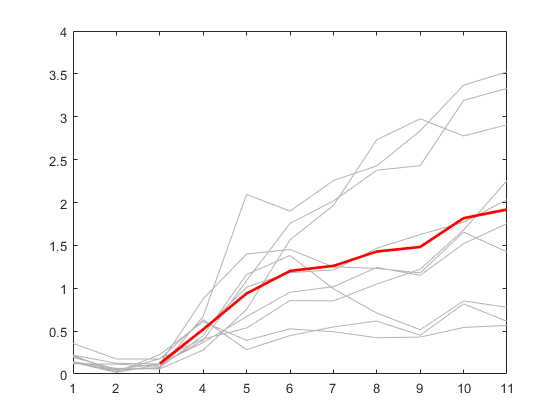

plot([cko1.numLevels:-1:1],cko1.mean,'r','LineWidth',2)

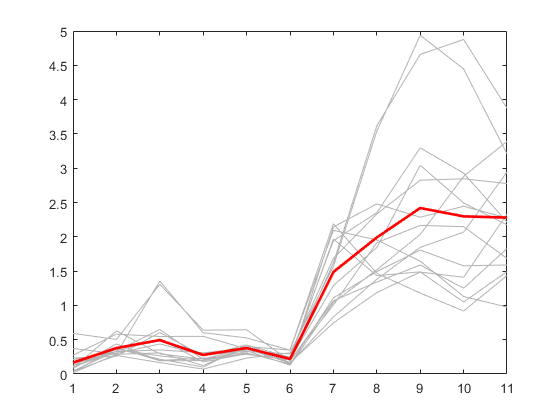


figure;
for x = 1:cko2.numROI
    plot([cko2.numLevels:-1:1],[cko2.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko2.numLevels
    cko2.mean(y) = mean([cko2.ROIdF(y,:).max]);
    cko2.meanfull(y) = mean([cko2.ROIdF(y,:).max]);
     if cko2.mean(y) < minLevel
        cko2.mean(y) = NaN
    end
end
plot([cko2.numLevels:-1:1],cko2.mean,'r','LineWidth',2)

figure;
for x = 1:cko3.numROI
    plot([cko3.numLevels:-1:1],[cko3.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko3.numLevels
    cko3.mean(y) = mean([cko3.ROIdF(y,:).max]);
    cko3.meanfull(y) = mean([cko3.ROIdF(y,:).max]);
     if cko3.mean(y) < minLevel
        cko3.mean(y) = NaN
    end
end

cko3 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×18 struct]
        ROIdF: [11×18 struct]
       WholeF: [1×11 struct]
       allROI: {1×18 cell}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 18
         mean: [1.5808 1.5077 1.4615 1.5147 1.6693 1.5454 0.8248 0.1283 0.1162 NaN]
     meanfull: [1.5808 1.5077 1.4615 1.5147 1.6693 1.5454 0.8248 0.1283 0.1162 0.0395]


cko3 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×18 struct]
        ROIdF: [11×18 struct]
       WholeF: [1×11 struct]
       allROI: {1×18 cell}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 18
         mean: [1.5808 1.5077 1.4615 1.5147 1.6693 1.5454 0.8248 0.1283 0.1162 NaN NaN]
     meanfull: [1.5808 1.5077 1.4615 1.5147 1.6693 1.5454 0.8248 0.1283 0.1162 0.0395 -0.0033]


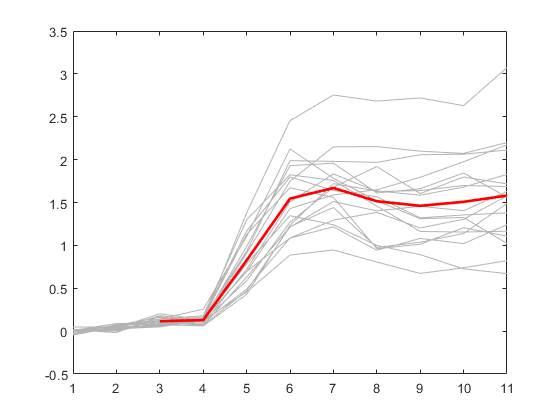

plot([cko3.numLevels:-1:1],cko3.mean,'r','LineWidth',2)


figure;
for x = 1:cko4.numROI
    plot([cko4.numLevels:-1:1],[cko4.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko4.numLevels
    cko4.mean(y) = mean([cko4.ROIdF(y,:).max]);
    cko4.meanfull(y) = mean([cko4.ROIdF(y,:).max]);
     if cko4.mean(y) < minLevel
        cko4.mean(y) = NaN
    end
end

cko4 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×23 struct]
        ROIdF: [11×23 struct]
       WholeF: [1×11 struct]
       allROI: {1×23 cell}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 23
         mean: [2.6095 2.4906 2.3802 1.9751 1.1170 0.3243 NaN]
     meanfull: [2.6095 2.4906 2.3802 1.9751 1.1170 0.3243 0.0780]


cko4 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×23 struct]
        ROIdF: [11×23 struct]
       WholeF: [1×11 struct]
       allROI: {1×23 cell}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 23
         mean: [2.6095 2.4906 2.3802 1.9751 1.1170 0.3243 NaN NaN]
     meanfull: [2.6095 2.4906 2.3802 1.9751 1.1170 0.3243 0.0780 0.0442]


cko4 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×23 struct]
        ROIdF: [11×23 struct]
       WholeF: [1×11 struct]
       allROI: {1×23 cell}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 23
         mean: [2.6095 2.4906 2.3802 1.9751 1.1170 0.3243 NaN NaN 0.1163 0.1295 NaN]
     meanfull: [2.6095 2.4906 2.3802 1.9751 1.1170 0.3243 0.0780 0.0442 0.1163 0.1295 0.0551]


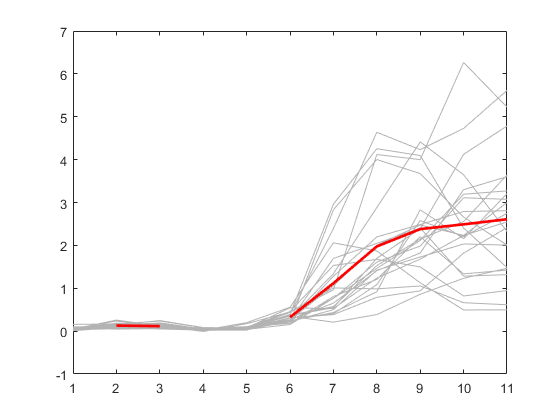

plot([cko4.numLevels:-1:1],cko4.mean,'r','LineWidth',2)

minLevel = 0.1;

figure;
for x = 1:cko5.numROI
    plot([cko5.numLevels:-1:1],[cko5.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:cko5.numLevels
    cko5.mean(y) = mean([cko5.ROIdF(y,:).max]);
    cko5.meanfull(y) = mean([cko5.ROIdF(y,:).max]);
     if cko5.mean(y) < minLevel
        cko5.mean(y) = NaN
    end
end

cko5 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×22 struct]
        ROIdF: [11×22 struct]
       WholeF: [1×11 struct]
       allROI: {1×23 cell}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 22
         mean: [2.6527 2.4186 1.9760 1.3053 0.8606 0.1781 0.1372 0.1079 NaN]
     meanfull: [2.6527 2.4186 1.9760 1.3053 0.8606 0.1781 0.1372 0.1079 0.0717]


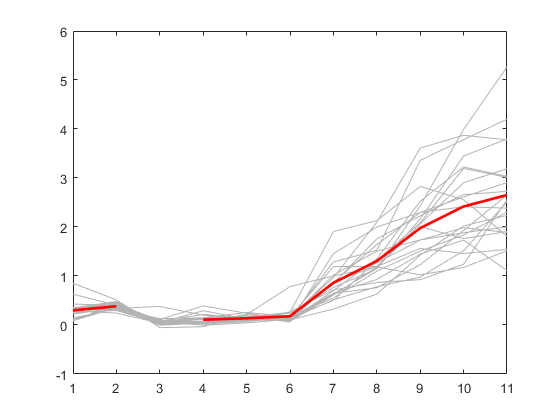

plot([cko5.numLevels:-1:1],cko5.mean,'r','LineWidth',2)

figure;
for x = 1:con1.numROI
    plot([con1.numLevels:-1:1],[con1.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con1.numLevels
    con1.mean(y) = mean([con1.ROIdF(y,:).max]);
    con1.meanfull(y) = mean([con1.ROIdF(y,:).max]);
     if con1.mean(y) < minLevel
        con1.mean(y) = NaN
    end
end

con1 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×27 struct]
        ROIdF: [11×27 struct]
       WholeF: [1×11 struct]
       allROI: {1×27 cell}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 27
         mean: [1.5019 1.3096 1.2666 1.3749 1.4905 1.6154 1.5588 1.2014 0.3499 0.2386 NaN]
     meanfull: [1.5019 1.3096 1.2666 1.3749 1.4905 1.6154 1.5588 1.2014 0.3499 0.2386 0.0811]


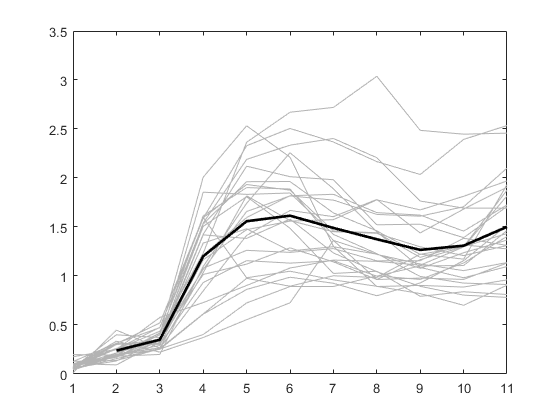

plot([con1.numLevels:-1:1],con1.mean,'k','LineWidth',2)


figure;
for x = 1:con2.numROI
    plot([con2.numLevels:-1:1],[con2.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con2.numLevels
    con2.mean(y) = mean([con2.ROIdF(y,:).max]);
    con2.meanfull(y) = mean([con2.ROIdF(y,:).max]);
     if con2.mean(y) < minLevel
        con2.mean(y) = NaN
    end
end

con2 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×8 struct]
        ROIdF: [11×8 struct]
       WholeF: [1×11 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 8
         mean: [1.6832 1.6445 1.4875 1.2500 1.4203 1.3083 1.2029 0.4904 NaN]
     meanfull: [1.6832 1.6445 1.4875 1.2500 1.4203 1.3083 1.2029 0.4904 0.0671]


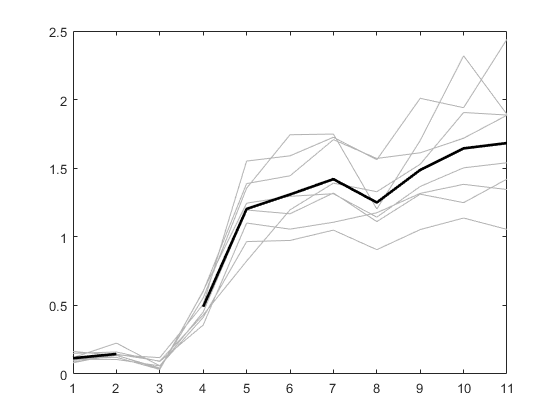

plot([con2.numLevels:-1:1],con2.mean,'k','LineWidth',2)


figure;
for x = 1:con3.numROI
    plot([con3.numLevels:-1:1],[con3.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con3.numLevels
    con3.mean(y) = mean([con3.ROIdF(y,:).max]);
    con3.meanfull(y) = mean([con3.ROIdF(y,:).max]);
     if con3.mean(y) < minLevel
        con3.mean(y) = NaN
    end
end

con3 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×10 struct]
        ROIdF: [11×10 struct]
       WholeF: [1×11 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 10
         mean: [1.1512 1.8253 1.0949 0.3177 NaN]
     meanfull: [1.1512 1.8253 1.0949 0.3177 0.0764]


con3 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×10 struct]
        ROIdF: [11×10 struct]
       WholeF: [1×11 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 10
         mean: [1.1512 1.8253 1.0949 0.3177 NaN 0.1250 0.2184 NaN]
     meanfull: [1.1512 1.8253 1.0949 0.3177 0.0764 0.1250 0.2184 0.0782]


con3 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×10 struct]
        ROIdF: [11×10 struct]
       WholeF: [1×11 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 10
         mean: [1.1512 1.8253 1.0949 0.3177 NaN 0.1250 0.2184 NaN 0.1300 NaN]
     meanfull: [1.1512 1.8253 1.0949 0.3177 0.0764 0.1250 0.2184 0.0782 0.1300 0.0408]


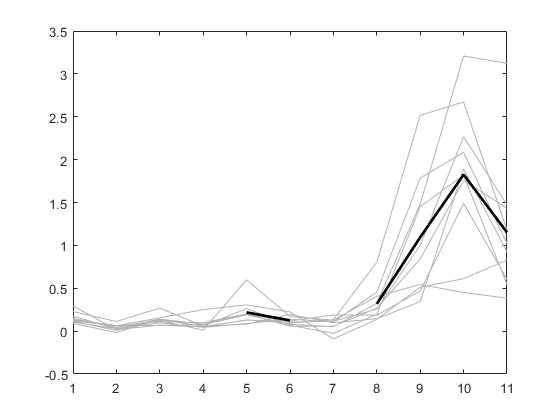

plot([con3.numLevels:-1:1],con3.mean,'k','LineWidth',2)


figure;
for x = 1:con4.numROI
    plot([con4.numLevels:-1:1],[con4.ROIdF(:,x).max],'Color',[0.7 0.7 0.7])
    hold on
end
for y = 1:con4.numLevels
    con4.mean(y) = mean([con4.ROIdF(y,:).max]);
    con4.meanfull(y) = mean([con4.ROIdF(y,:).max]);
     if con4.mean(y) < minLevel
        con4.mean(y) = NaN
    end
end

con4 = struct with fields:
     ICstruct: [1×1 struct]
         ROIF: [11×10 struct]
        ROIdF: [11×10 struct]
       WholeF: [1×11 struct]
       allROI: {[256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]  [256×256 logical]}
     neuroPil: [256×256 logical]
    numLevels: 11
       numROI: 10
         mean: [1.1126 1.1088 0.7922 0.9483 0.6697 0.1743 NaN]
     meanfull: [1.1126 1.1088 0.7922 0.9483 0.6697 0.1743 0.0532]


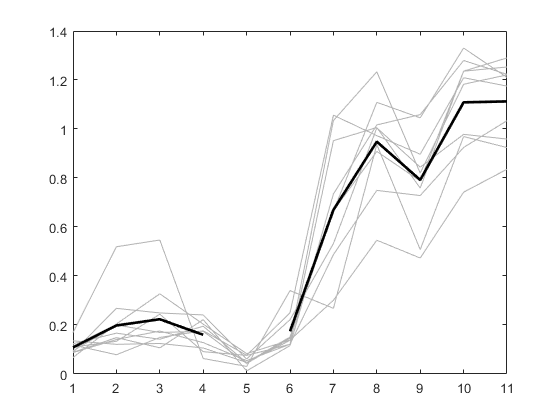

plot([con4.numLevels:-1:1],con4.mean,'k','LineWidth',2)

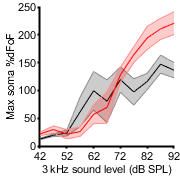

Ckocells = [cko1.numROI,cko2.numROI,cko3.numROI,cko4.numROI,cko5.numROI];
Concells = [con1.numROI,con2.numROI,con3.numROI,con4.numROI];
conMeanMatx = [];
ckoMeanMatx = [];
for y = 1:con1.numLevels
    con3khzmean(y) = nanmean([con1.mean(y),con2.mean(y),con3.mean(y),con4.mean(y)]);
    conMeanMatx = [conMeanMatx;[con1.mean(y),con2.mean(y),con3.mean(y),con4.mean(y)]];
    con3khzSEM(y) = nanstd([con1.mean(y),con2.mean(y),con3.mean(y),con4.mean(y)])/sqrt(4);
end
for y = 1:cko1.numLevels
    cko3khzmean(y) = nanmean([cko1.mean(y),cko2.mean(y),cko3.mean(y),cko4.mean(y),cko5.mean(y)]);
    ckoMeanMatx = [ckoMeanMatx; [cko1.mean(y),cko2.mean(y),cko3.mean(y),cko4.mean(y),cko5.mean(y)]];
    cko3khzSEM(y) = nanstd([cko1.mean(y),cko2.mean(y),cko3.mean(y),cko4.mean(y),cko5.mean(y)])/sqrt(5);
    
end
% plot([con4.numLevels:-1:1],con6khzmean,'k','LineWidth',2)
% plot([con4.numLevels:-1:1],cko6khzmean,'r','LineWidth',2)
figure
shadedErrorBar([con1.numLevels:-1:1],con3khzmean*100,con3khzSEM*100)
hold on
shadedErrorBar([con1.numLevels:-1:1],cko3khzmean*100,cko3khzSEM*100,'lineprops','r')
ylabel('Max soma %dFoF')
xlabel('3 kHz sound level (dB SPL)')
xticks([1 3 5 7 9 11])
xticklabels({'42','52','62','72','82','92'})
xlim([1 11])
ylim([0 250])
figQuality(gcf,gca,[1.87 1.87])

%print(gcf,'-dpdf')


% by cell
conMax = []


conMax =

     []



j = 1;
for i = 1:con1.numROI
    for k = 1:con1.numLevels
    if [con1.ROIdF(k,i).max] < minLevel
        [con1.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con1.ROIdF(:,i).max]';
    j = j + 1;
end
for i = 1:con2.numROI
    for k = 1:con2.numLevels
    if [con2.ROIdF(k,i).max] < minLevel
        [con2.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con2.ROIdF(:,i).max]';
    j = j + 1;
end
for i = 1:con3.numROI
    for k = 1:con3.numLevels
    if [con3.ROIdF(k,i).max] < minLevel
        [con3.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con3.ROIdF(:,i).max]';
    j = j + 1;
end
 for i = 1:con4.numROI
    for k = 1:con4.numLevels
    if [con4.ROIdF(k,i).max] < minLevel
        [con4.ROIdF(k,i).max] = NaN;
    end
    end
    conMax(:,j) = [con4.ROIdF(:,i).max]';
    j = j + 1;
 end
 con3mean = nanmean(conMax,2);
 con3std = nanstd(conMax,0,2);
 
  % cKO 
 ckoMax = []


ckoMax =

     []



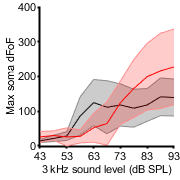

j = 1;
for i = 1:cko1.numROI
    for k = 1:cko1.numLevels
    if [cko1.ROIdF(k,i).max] < minLevel
        [cko1.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko1.ROIdF(:,i).max]';
    j = j + 1;
end
for i = 1:cko2.numROI
    for k = 1:cko2.numLevels
    if [cko2.ROIdF(k,i).max] < minLevel
        [cko2.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko2.ROIdF(:,i).max]';
    j = j + 1;
end
for i = 1:cko3.numROI
    for k = 1:cko3.numLevels
    if [cko3.ROIdF(k,i).max] < minLevel
        [cko3.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko3.ROIdF(:,i).max]';
    j = j + 1;
end
 for i = 1:cko4.numROI
    for k = 1:cko4.numLevels
    if [cko4.ROIdF(k,i).max] < minLevel
        [cko4.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko4.ROIdF(:,i).max]';
    j = j + 1;
 end
 for i = 1:cko5.numROI
    for k = 1:cko5.numLevels
    if [cko5.ROIdF(k,i).max] < minLevel
        [cko5.ROIdF(k,i).max] = NaN;
    end
    end
    ckoMax(:,j) = [cko5.ROIdF(:,i).max]';
    j = j + 1;
 end
 
 cko3mean = nanmean(ckoMax,2);
 cko3std = nanstd(ckoMax,0,2);
 
figure
shadedErrorBar([con4.numLevels:-1:1],con3mean*100,con3std*100)
hold on
shadedErrorBar([con4.numLevels:-1:1],cko3mean*100,cko3std*100,'lineprops','r')
ylabel('Max soma dFoF')
xlabel('3 kHz sound level (dB SPL)')
xticks([1 3 5 7 9 11])
xticklabels({'43','53','63','73','83','93'})
xlim([1 11])
figQuality(gcf,gca,[1.87 1.87])

%print(gcf,'-dpdf')
 

% LME model, by cell
locationBase = {'1' '2','3','4','5','6','7','8','9','10','11'}; 
genoBasecon = {'con','con','con','con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'};
mouse1Basecon = {'M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M1'};
mouse2Basecon = {'M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2'};
mouse3Basecon = {'M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3'};
mouse4Basecon = {'M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4'};
mouse5Basecon = {'M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5'};
mouse6Basecon = {'M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6'};
mouse7Basecon = {'M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7'};
mouse8Basecon = {'M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8'};
mouse9Basecon = {'M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9'};

mouse1con = [mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon,mouse1Basecon];
mouse2con = [mouse2Basecon,mouse2Basecon,mouse2Basecon,mouse2Basecon,mouse2Basecon,mouse2Basecon,mouse2Basecon,mouse2Basecon];
mouse3con = [mouse3Basecon,mouse3Basecon,mouse3Basecon,mouse3Basecon,mouse3Basecon,mouse3Basecon,mouse3Basecon,mouse3Basecon,mouse3Basecon,mouse3Basecon];
mouse4con = [mouse4Basecon,mouse4Basecon,mouse4Basecon,mouse4Basecon,mouse4Basecon,mouse4Basecon,mouse4Basecon,mouse4Basecon,mouse4Basecon,mouse4Basecon];

mousecon = [mouse1con,mouse2con,mouse3con,mouse4con];

mouse1cko = [mouse5Basecon,mouse5Basecon,mouse5Basecon,mouse5Basecon,mouse5Basecon,mouse5Basecon,mouse5Basecon,mouse5Basecon,mouse5Basecon,mouse5Basecon];
mouse2cko = [mouse6Basecon,mouse6Basecon,mouse6Basecon,mouse6Basecon,mouse6Basecon,mouse6Basecon,mouse6Basecon,mouse6Basecon,mouse6Basecon,mouse6Basecon,mouse6Basecon,mouse6Basecon,mouse6Basecon,mouse6Basecon,mouse6Basecon];
mouse3cko = [mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon,mouse7Basecon];
mouse4cko = [mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon,mouse8Basecon];
mouse5cko = [mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon,mouse9Basecon];
mousecko = [mouse1cko,mouse2cko,mouse3cko,mouse4cko,mouse5cko];

mouse1loc = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
mouse2loc = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
mouse3loc = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
mouse4loc = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
mouse5loc = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
mouse6loc = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
mouse7loc = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
mouse8loc = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
mouse9loc = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase];
loc = [mouse1loc,mouse2loc,mouse3loc,mouse4loc,mouse5loc,mouse6loc,mouse7loc,mouse8loc,mouse9loc]';
genocon1 = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon]; % 27 cells
genocon2 = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon]; % 8 cells
genocon3 = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon]; % 10 cells
genocon4 = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon]; % 10 cells

genoCon = [genocon1,genocon2,genocon3,genocon4];

genocko1 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 10 cells
genocko2 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 15 cells
genocko3 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 18 cells
genocko4 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 23 cells
genocko5 = [genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]; % 22 cells

genoCko = [genocko1,genocko2,genocko3,genocko4,genocko5];
conVal = reshape(conMax,605,1);
ckoVal = reshape(ckoMax,968,1);
geno = [genoCon,genoCko]';
mouse = [mousecon,mousecko]';

maxVal = [conVal',ckoVal']';
tbl = table(geno,mouse,loc,maxVal,'VariableNames',{'Genotype','Mouse','Location','Max'})

tbl = 1573×4 table
    Genotype    Mouse     Location      Max  
    ________    ______    ________    _______

    {'con'}     {'M1'}     {'1' }      2.5353
    {'con'}     {'M1'}     {'2' }      2.3934
    {'con'}     {'M1'}     {'3' }      2.0358
    {'con'}     {'M1'}     {'4' }      2.1672
    {'con'}     {'M1'}     {'5' }      2.3671
    {'con'}     {'M1'}     {'6' }      2.5057
    {'con'}     {'M1'}     {'7' }      2.3291
    {'con'}     {'M1'}     {'8' }      1.5901
    {'con'}     {'M1'}     {'9' }     0.47281
    {'con'}     {'M1'}     {'10'}     0.31395
    {'con'}     {'M1'}     {'11'}     0.12755
    {'con'}     {'M1'}     {'1' }      2.4577
    {'con'}     {'M1'}     {'2' }      2.4471
    {'con'}     {'M1'}     {'3' }      2.4863
    {'con'}     {'M1'}     {'4' }       3.038
    {'con'}     {'M1'}     {'5' }      2.7203


lme = fitlme(tbl,'Max~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml') 

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations            1304
    Fixed effects coefficients           2
    Random effects coefficients         20
    Covariance parameters                3

Formula:
    Max ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2827.6    2853.5    -1408.8          2817.6  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat     DF      pValue        Lower        Upper  
    {'(Intercept)' }        0.78234     0.22699    3.4466    1302    0.00058586      0.33703     1.2277
    {'Genotype_cko'}        0.30398     0.15456    1.9667    1302      0.049428    0.0007623    0.60719

Random effects covariance parameters (95% CIs):
Group: Location (11 Levels)
    Name1                  Name2              

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta =     0.7823
    0.3040


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE         tStat     DF        pValue       Lower        Upper 
    {'(Intercept)' }        0.78234     0.22699    3.4466     15.31    0.0035054      0.29937    1.2653
    {'Genotype_cko'}        0.30398     0.15456    1.9667    6.9586      0.09017    -0.061942    0.6699
